# **EECE5666 (DSP) : Homework-6**

**Due on April 8, 2022 by 11:59 pm via submission portal. **

**NAME**: McKean, Tyler

## **Instructions**

- You are required to complete this assignment using Live Editor.

- Enter your MATLAB script in the spaces provided. If it contains a plot, the plot will be displayed after the script.

- All your plots must be properly labeled and should have appropriate titles to get full credit.

- Use the equation editor to typeset mathematical material such as variables, equations, etc. 

- After completeing this assignment, export this Live script to PDF and submit the PDF file through the provided submission portal.

- You will have only one attempt to submit your assignment. Make every effort to submit the correct and completed PDF file the first time.

- Please submit your homework before the due date/time. A late submission after midnight of the due date will result in loss of points at a rate of 10% per hour until 8 am the following day, at which time the solutions will be published.

## **Default Plot Parameters**

set(0,'defaultfigurepaperunits','points','defaultfigureunits','points');
set(0,'defaultaxesfontsize',10); set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultaxestitlefontsize',1.4,'defaultaxeslabelfontsize',1.2);

## Problem 6.1

#### Text Problem 10.21 (Page-615)

clc; close all; clear;

**(a)** Design the following MATLAB function that implements conversions between various filter specifications, as described in the comments below in the code example.

**MATLAB function**: Provide your function code below in the code example for the TA to grade and enter your function at the end of the file.

**(b)** Convert the following relative (dB) specifications into (i) absolute and (ii) analog specifications:

$A_\mathrm{p} = 0.5$ dB and $A_\mathrm{s} = 40$ dB

**(i) Absolute specs:** 

Ap = 0.5; As = 40;
[dp,ds] = spec_convert(Ap,As,'rel','abs')

dp = 0.0288

ds = 0.0103

**(ii) Analog specs:**

[epsilon,A] = spec_convert(Ap,As,'rel','ana')

epsilon = 0.3493

A = 100

**(c)** Convert the following absolute (dB) specifications into (i) relative and (ii) analog specifications:

$\delta_\mathrm{p} = 0.01$ and $\delta_\mathrm{s} = 0.001$

**(i) Relative specs:** 

dp = 0.01; ds = 0.001;
[Ap,As] = spec_convert(dp,ds,'abs','rel')

Ap = 0.1737

As = 60

**(ii) Analog specs:**

[epsilon, A] = spec_convert(dp,ds,'abs','ana')

epsilon = 0.2020

A = 1000

## Problem 6.2

#### **Text Problem 10.28 (Page 616)** 

Design a lowpass FIR filter to satisfy the specifications: $\omega_\mathrm{p}=0.3\mathrm{\pi},$ $A_\mathrm{p}=0.5$dB, $\omega_\mathrm{s}=0.5\mathrm{\pi},$ and $A_\mathrm{s}=50$ dB.

clc; close all; clear;

**(a)** Use an appropriate fixed window to obtain the minimum length linear-phase filter impulse response. Provide a plot similar to Figure~10.12 in the textbook. Do not use the `fir1` function.

**Solution:** 

Because the desired stopband attenuation is 50 dB, we will choose the Hamming window since it has the closest Min. Stopband Attenuation

% Design Specifications
ws = 0.5*pi; wp = 0.3*pi; 
deltaW = ws-wp; wc = (wp+ws)/2; 
As = 50; Ap = 0.5;
[deltap,deltas] = spec_convert(Ap,As,'rel','abs');
% Solve for FIR Filter Type and order M
L = ceil(6.6*pi/deltaW)+1; M = L-1;

Here, we have calculated the length the filter to be $L = 34$ samples and our order $M = 33$

Thus, this filter will be a Type-II FIR filter

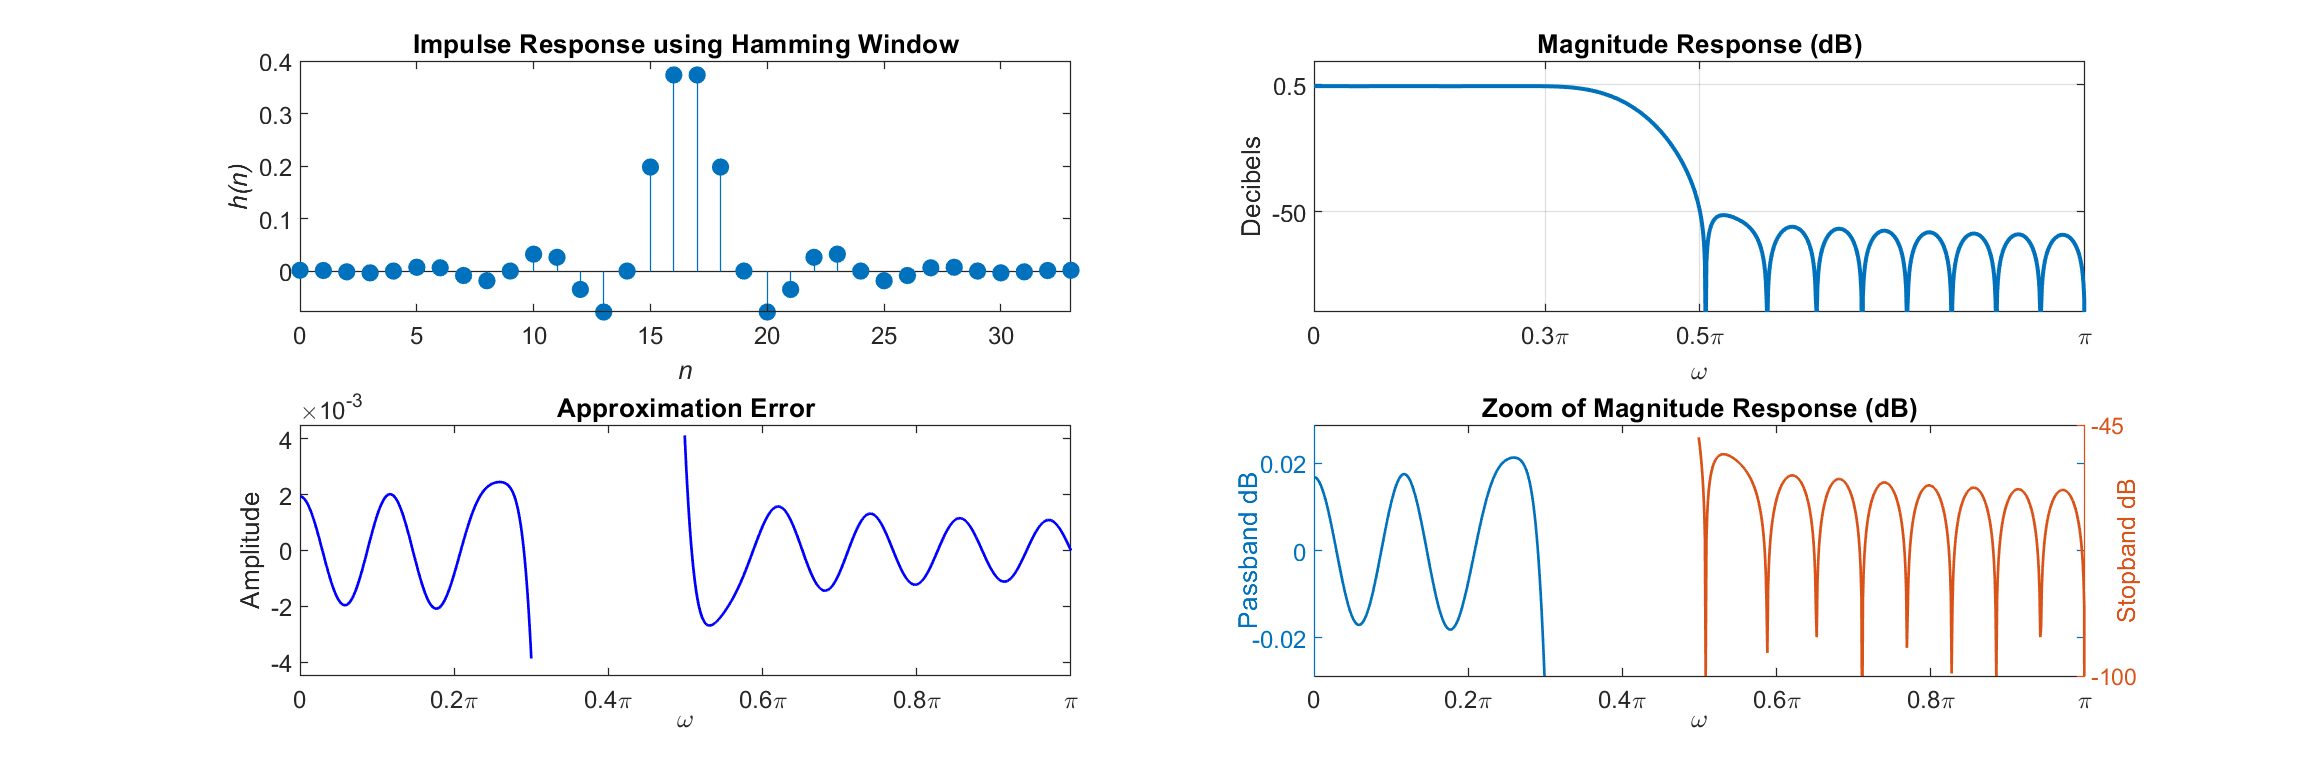

% Approximate the Impulse Response using Ideal LPF and Hamming Window
n = 0:M; hd = ideal_lp(wc,L)'; h = hd.*hamming(L); 
% Frequency Response
w = linspace(0,pi,1001); H = freqz(h,1,w); Dom = pi/1000;
Ip = ceil(wp/Dom); Is = floor(ws/Dom); 
Ip1 = ceil((wp+0.05*pi)/Dom); Is1 = ceil(0.4*pi/Dom);
[Hr,om] = zerophase(h,1,w);
figure('Units','inches','Position',[0,0,12,4]); 
% Impulse Response Plot
subplot(2,2,1), stem(n,h,'filled'), xlim([0 M])
xlabel('\it{n}'), ylabel('\it{h(n)}')
title('Impulse Response using Hamming Window')
% Magnitude Response in dB
magdb = mag2db(abs(H));
Hmag = abs(H);
Hdb = 20*log10(Hmag./max(Hmag));
subplot(2,2,2), plot(w/pi,Hdb, "LineWidth",1.5), grid on 
title('Magnitude Response (dB)')
xlabel('\omega'), xticks([0 0.3 0.5 1]), 
xticklabels({'0','0.3\pi','0.5\pi','\pi'});
ylabel('Decibels'), yticks([-50 0.5]), ylim([-90 10])
% Approximation Error Plot
subplot(2,2,3); 
plot(om(1:Ip+1)/pi,Hr(1:Ip+1)-1,'b',om(Is+1:end)/pi,Hr(Is+1:end),'b','linewidth',1); 
axis([0,1,-0.0035,0.0035]); 
title('Approximation Error','fontsize',10);
ylabel('Amplitude'), ylim([-.0045 .0045])
xlabel('\omega','VerticalAlignment','middle');
set(gca,'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
% Zoom of Log-Magnitude Plot
subplot(2,2,4); 
[AX,H1,H2] = plotyy(om(1:Ip+1)/pi,magdb(1:Ip+1),...
    om(Is+1:end)/pi,magdb(Is+1:end)); 
set(H1,'linewidth',1); set(H2,'linewidth',1);
title('Zoom of Magnitude Response (dB)','fontsize',10);
xlabel('\omega','VerticalAlignment','middle');
set(get(AX(1),'Ylabel'),'String','Passband dB',...
    'VerticalAlignment','middle');
set(get(AX(2),'Ylabel'),'String','Stopband dB',...
    'VerticalAlignment','bottom');
set(AX(1),'YLim',[-deltap,deltap]); set(AX(2),'YLim',[-100,-45]);
set(AX(2),'Ytick',[-100,-45]);
set(AX(1),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(AX(2),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 

**(b)** Repeat (a) using the Kaiser window and compare the lengths of the resulting filters. Use the `fir1` function for the design.

**Solution:**

% Obtain Absolute Specifications and Calculate Beta for Kaiser Window
[dp,ds] = spec_convert(Ap,As,'rel','abs'); 
d = min(dp,ds); A = ceil(-20*log10(d));
% A is between 21 <= A <= 50, so use 2nd equation for Beta from (10.84)
Beta = 0.5842*(A-21)^(0.4) + 0.07886*(A-21);
Mk = ceil((A - 8)/(2.285*deltaW));

Here I've calculate that the necessary value of $\beta = 4.5335$ and length $M = 30$ for our Kaiser window function, which is 3 values shorter in length than the Hamming window used in part (a)

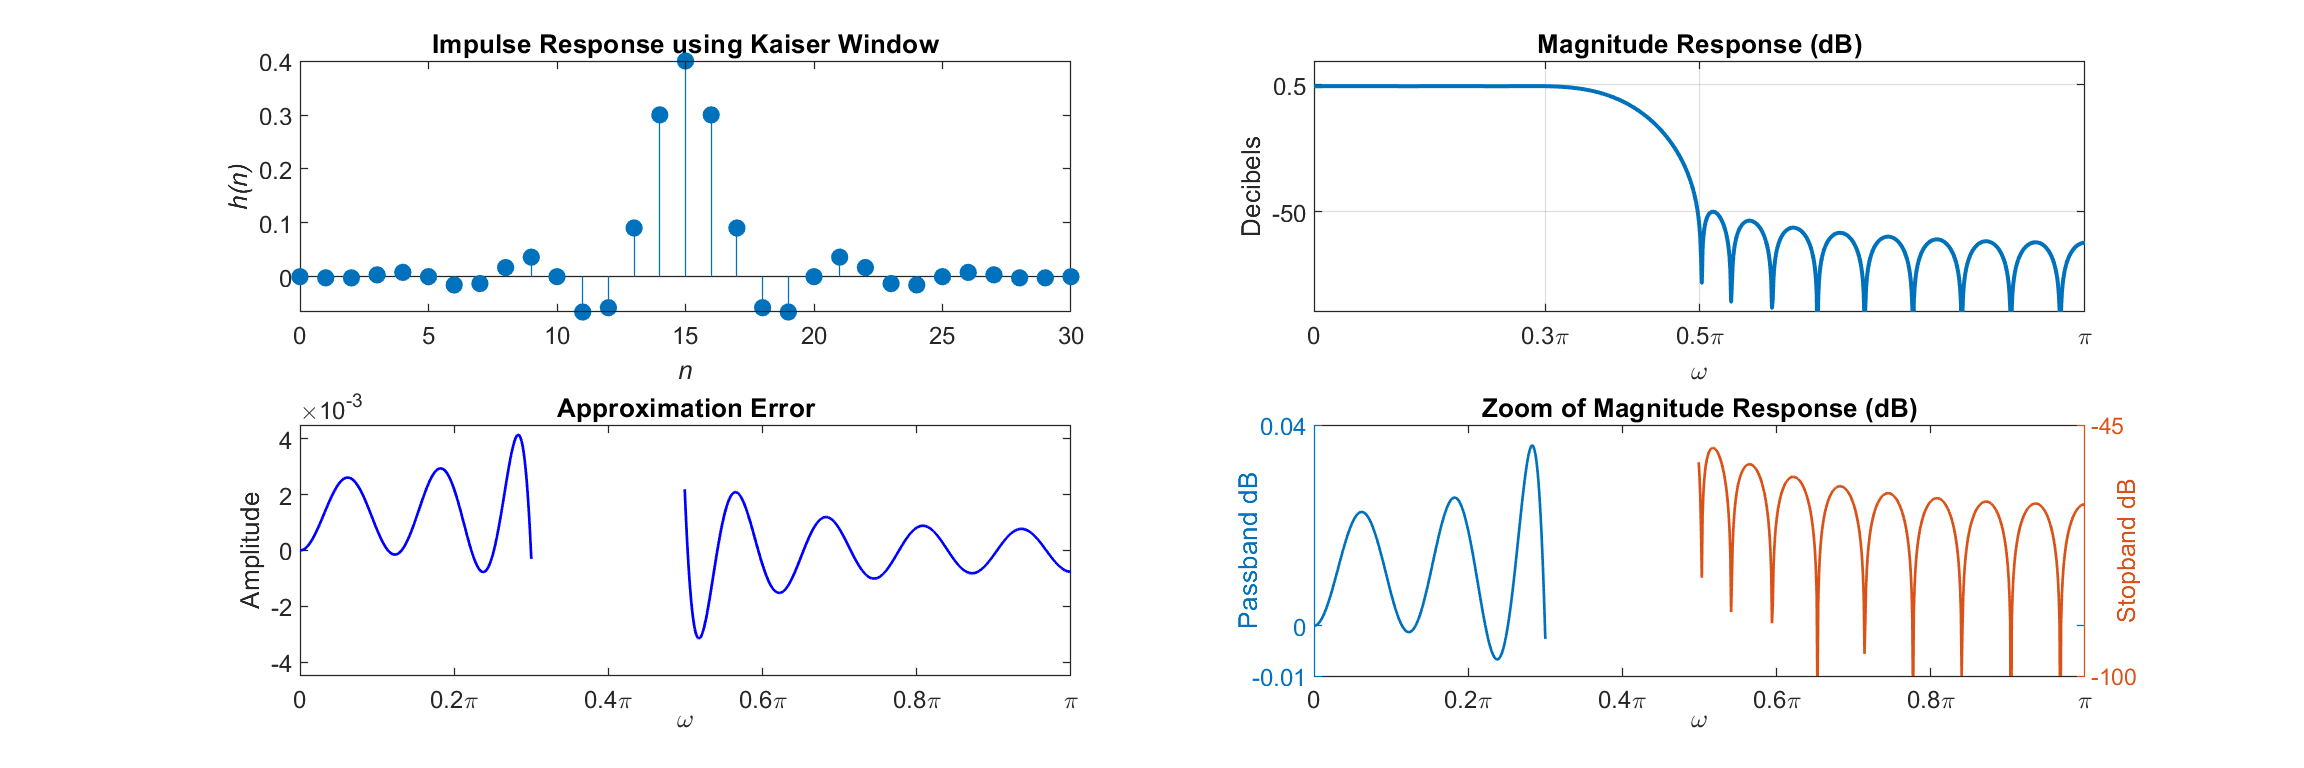

% Generate Impulse Response using fir1() function
nk = 0:Mk; hk = fir1(Mk,wc/pi,kaiser(Mk+1,Beta));
% Frequency Response
wk = linspace(0,pi,1001); Hk = freqz(hk,1,w); Dom = pi/1000;
Ip = ceil(wp/Dom); Is = floor(ws/Dom); 
Ip1 = ceil((wp+0.05*pi)/Dom); Is1 = ceil(0.4*pi/Dom);
[Hr,om] = zerophase(hk,1,wk); Hmag = abs(Hk);
magdb = mag2db(Hmag);
Hdb = 20*log10(Hmag./max(Hmag));
% Plot Results
figure('Units','inches','Position',[0,0,12,4]); 
% Impulse Response Plot
subplot(2,2,1), stem(nk,hk,'filled')
xlabel('\it{n}'), ylabel('\it{h(n)}')
title('Impulse Response using Kaiser Window')
% Magnitude Response Plot
subplot(2,2,2), plot(w/pi,Hdb,'LineWidth',1.5)
grid on, title('Magnitude Response (dB)')
xlabel('\omega'), xticks([0 0.3 0.5 1])
xticklabels({'0','0.3\pi','0.5\pi','\pi'});
ylabel('Decibels'), yticks([-50 0.5])
ylim([-90 10])
% Approximation Error Plot
subplot(2,2,3); 
plot(om(1:Ip+1)/pi,Hr(1:Ip+1)-1,'b',om(Is+1:end)/pi,Hr(Is+1:end),'b','linewidth',1); 
axis([0,1,-0.0035,0.0035]); 
title('Approximation Error','fontsize',10);
ylabel('Amplitude'), ylim([-.0045 .0045])
xlabel('\omega','VerticalAlignment','middle');
set(gca,'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
% Zoom of Log-Magnitude Plot
subplot(2,2,4); 
[AX,H1,H2] = plotyy(om(1:Ip+1)/pi,magdb(1:Ip+1),...
    om(Is+1:end)/pi,magdb(Is+1:end)); 
set(H1,'linewidth',1); set(H2,'linewidth',1);
title('Zoom of Magnitude Response (dB)','fontsize',10);
xlabel('\omega','VerticalAlignment','middle');
set(get(AX(1),'Ylabel'),'String','Passband dB',...
    'VerticalAlignment','middle');
set(get(AX(2),'Ylabel'),'String','Stopband dB',...
    'VerticalAlignment','bottom');
set(AX(1),'YLim',[-0.01,0.04]); set(AX(2),'YLim',[-100,-45]);
set(AX(1),'Ytick',[-0.01,0, 0.04]); set(AX(2),'Ytick',[-100,-45]); 
set(AX(1),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(AX(2),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 

**(c) **Provide a comparison between the two designs in terms of their frequency responses and filter order.

**Comparison**:  

Both FIR filters achieved a similar sidelobe level of -50dB, despite using two different window functions (Hamming and Kaiser). 

The impulse response using the Hamming window had a value of $M = 33$ order FIR filter, while the Kaiser window approach achieved the desired specifications using only order $M = 30$ FIR filter. Thus, the Kaiser window approach was able to satisfy the same design specifications as the Hamming window approach, but did so using 3 less samples. y

## Problem 6.3 

#### **Text Problem 7.33 (Page 617)** This is a revised version.

A bandpass filter is given by the specifications: $\omega_{\mathrm{s}_1}=0.2\mathrm{\pi},$ $A_{\mathrm{s}_1}=40$ dB, $\omega_{\mathrm{p}_1}=0.3\mathrm{\pi},$ $\omega_{\mathrm{p}_2}=0.5\mathrm{\pi},$ $A_{\mathrm{p}}=0.2$ dB, $\omega_{\mathrm{s}_2}=0.65\mathrm{\pi},$ and $A_{\mathrm{s}_2}=40$ dB.

clc; close all; clear;

**(a)** Choose $L = 45$ so that there are two samples in the transition band. Using a raised-cosine transition band samples obtain the filter response. Provide a plot of the log-magnitude and impulse responses. 

**Solution:** 

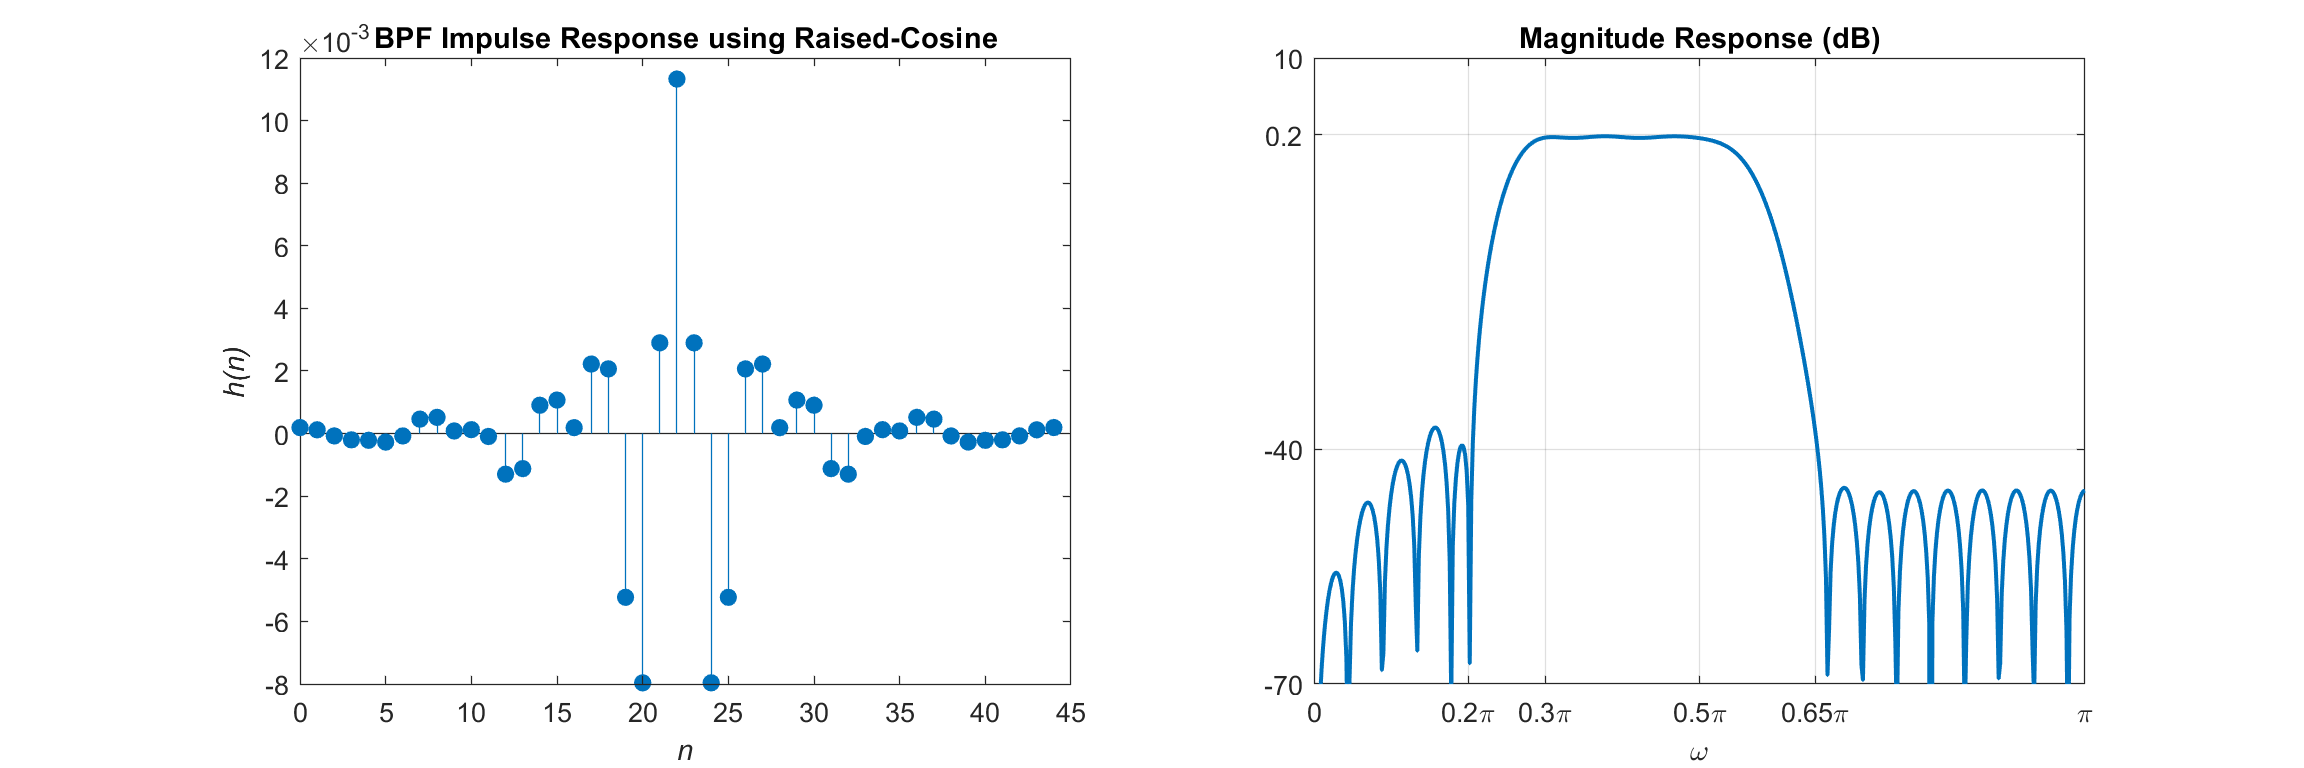

clc; close all; clear;
% Impulse Response Length = 45 using M = 44 order FIR filter
L = 45; M = L-1;
% Design Specifications
fs1 = 0.2; fp1 = 0.3; dw1 = fp1-fs1; wc1 = (fp1+fs1)/2;
fs2 = 0.65; fp2 = 0.5; dw2 = fs2-fp2; wc2 = (fp2+fs2)/2;
Ap = 0.2; As = 40; 
 % Phase Delay Parameters
alpha = (L-1)/2; Q = floor(alpha);
om = linspace(0,2*pi,1001);
% Frequency sample index and width between samples
k = 0:M; dw = 2/L;
% Desired Phase
psid = (-alpha*(-L/2:L/2-1)*dw*pi); psid = fftshift(psid);
% FIR Filter Design
ks1 = floor(fs1/dw)+1; ks2 = ceil(fs2/dw)+1; % Indices for samples nearest the two SB edges
kp1 = ceil(fp1/dw)+1; kp2 = floor(fp2/dw)+1; % Indices for samples nearest the two PB edges
lowtr = ((ks1+1):(kp1-1)); % Lower Transition band sample indices
hightr = ((kp2+1):(ks2-1)); % Upper Transition band sample indices
Alow = 0.5-0.5*cos((fs1-(lowtr-1)*dw)./(fs1-fp1)*pi); % Lower Transition band samples
Aupper = 0.5-0.5*cos((fs2-(hightr-1)*dw)./(fs2-fp2)*pi); % Higher Transition band samples
A1 = [zeros(1,ks1),Alow,ones(1,kp2-kp1+1),Aupper,zeros(1,floor(L/2)-ks2+2)];
Ad = [A1(1:end),fliplr(A1(2:end))];
% Desired Freq Resp Samples
Hd = Ad.*exp(1i*psid); 
% Desired Impulse Response
n = 0:M; h = real(ifft(Hd)); 
% Plot
figure('Units','inches','Position',[0,0,12,4]);
% Impulse Response Plot
subplot(1,2,1), stem(n,h,'filled')
title('BPF Impulse Response using Raised-Cosine')
xlabel('\it{n}'), xlim([0 L]), ylabel('\it{h(n)}')
subplot(1,2,2), [db,mag,pha,grd,w] = freqz_m(h,1)
plot(w/pi,db,'LineWidth',1.5)
grid on, title('Magnitude Response (dB)'), ylim([-70 10])
xlabel('\omega'), xticks([0 0.2 0.3 0.5 0.65 1]), 
yticks([-70 -40 0.2 10])
xticklabels({'0','0.2\pi','0.3\pi','0.5\pi','0.65\pi','\pi'}); 

Does this design satisfy the given specifications?

**Answer:** 

This Bandpass FIR filter with $L = 45$ comes close to the design specifications, but does not completely satisfy them. As we can see from the Magnitude Response plot, the sidelobe levels at the stopband value of $\omega_{s1} = 0.2\pi $ are not completely met with the desired stopband attentuation value of $A_s = 40 $ dB. We would need to evaluate this filter design using a different order of $M$until our design specifications are satisfied. 

**(b)** Repeat (a) using the `fir2` function and the Hann window. 

**Solution:** 

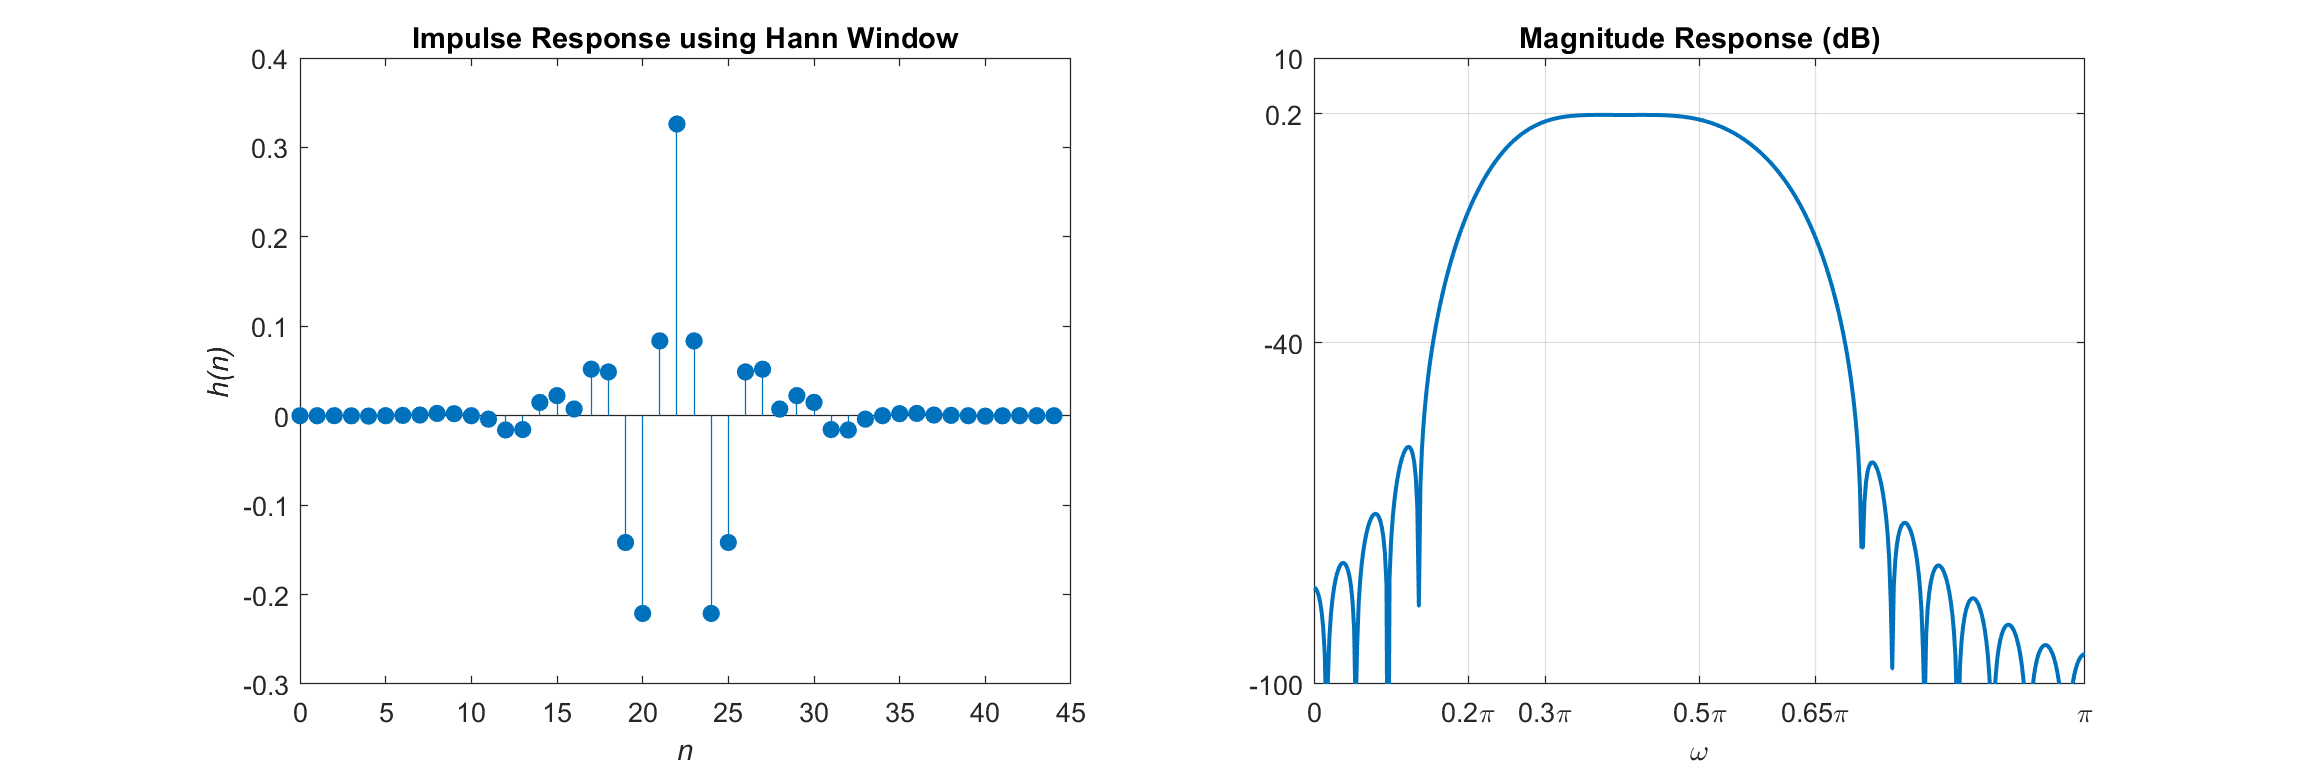

% Generate Impulse Response using fir2() function
L = 45; M = L-1;
h = fir2(M,[0 fs1 fp1 fp2 fs2 1],[0 0 1 1 0 0], hann(L)); 
n = 0:L-1; 
% Generate Frequency Response
[db,mag,pha,grd,w] = freqz_m(h,1); 
% Plot Results
figure('Units','inches','Position',[0,0,12,4]); 
% Impulse Response Plot
subplot(1,2,1), stem(n,h,'filled')
xlabel('\it{n}'), xlim([0 L]) 
ylabel('\it{h(n)}')
title('Impulse Response using Hann Window')
subplot(1,2,2), plot(w/pi,db,'LineWidth',1.5)
grid on 
title('Magnitude Response (dB)')
ylim([-100 10]), xlabel('\omega')
yticks([-100 -40 0.2 10]), xticks([0 0.2 0.3 0.5 0.65 1])

xticklabels({'0','0.2\pi','0.3\pi','0.5\pi','0.65\pi','\pi'});  

Does this design satisfy the given specifications?

**Answer:** 

We observe that even when using the **fir2** function, the design specification is not satisfied. The mainlobe of the filter is too wide and does not satisfy the stopband requirements at $\omega_{s1} = 0.2\pi \text{ and } \omega_{s2} = 0.65\pi$. 

## Problem 6.4

#### **Text Problem 7.35 (Page 617)** 

Design of a length $L=50$ FIR differentiator. 

clc; close all; clear;

**(a)** Design the above described differentiator using the frequency sampling method and provide graphs of impulse and amplitude responses of the designed differentiator in one figure window using two rows and one column.

**Solution:** 

**MATLAB script**: 

L = 50; % Length of Impulse Response
M = L-1; n = 0:L-1; % Order of FIR is M = 49
Dom = 2*pi/L; alpha = (L-1)/2;
w = (0:L-1)*Dom;
index = w >= pi;
w(index) = w(index) - 2*pi;
% Desired Freq Resp Samples
Hd =  -j*w.*exp(-j*w*alpha);
% Desired Impulse Response
n = 0:M; hd = real(ifft(Hd));
h = hd.*hamming(L)';
% Desired Amplitude Response
omega = linspace(0,2*pi,1001);
[Hamp wt P2 L2] = amplresp(h(:)',omega);

*** Type-4 Linear-Phase Filter ***


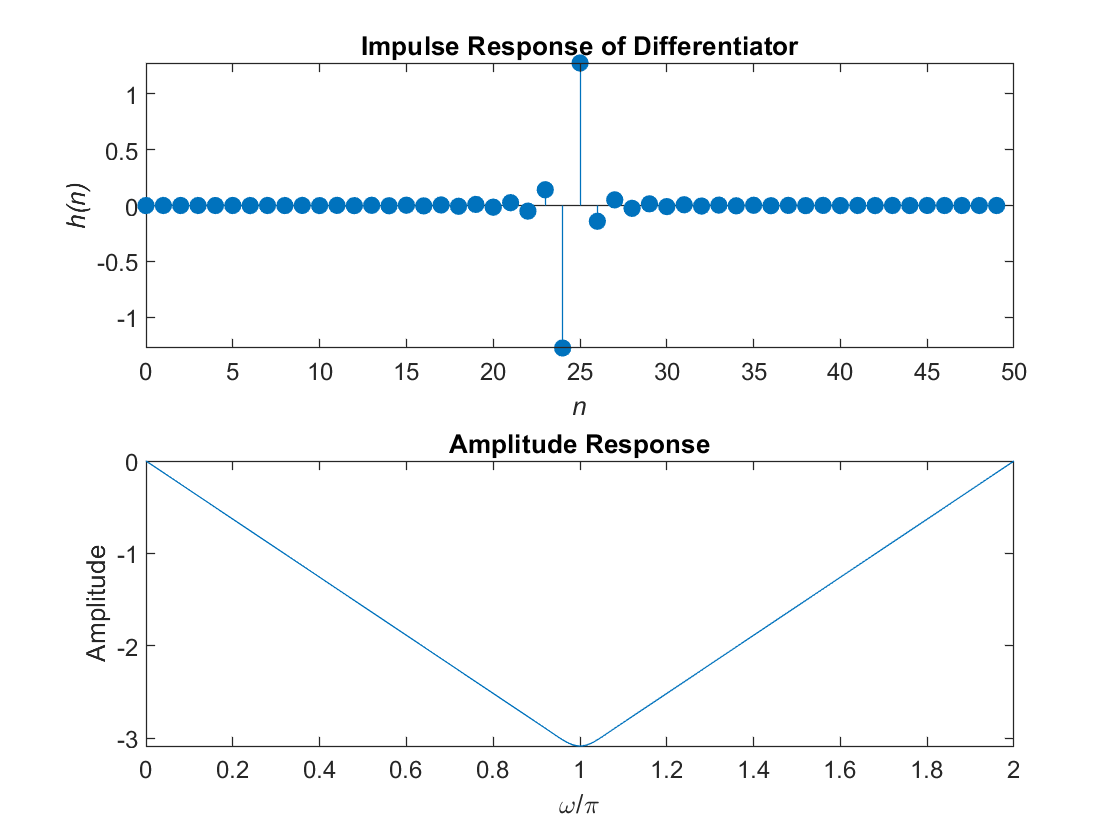

figure, subplot(2,1,1), stem(n,h,'filled')
title('Impulse Response of Differentiator')
xlabel('\it{n}'); ylabel('\it{h(n)}')
subplot(2,1,2), plot(omega/pi,Hamp)

title('Amplitude Response')
xlabel('\omega/\pi'), ylabel('Amplitude')

**(b)** Generate $151$ samples of the signal $x[n]=10\cos(0.2\mathrm{\pi} n),$ $0\leq n\leq 150$ and process them through the differentiator designed in (a) to obtain $y[n].$ Provide stem plots of both $x[n]$ and $y[n]$ for $50\leq n\leq 100$ as $(2\times1)$subplots in one figure.

**Solution:** 

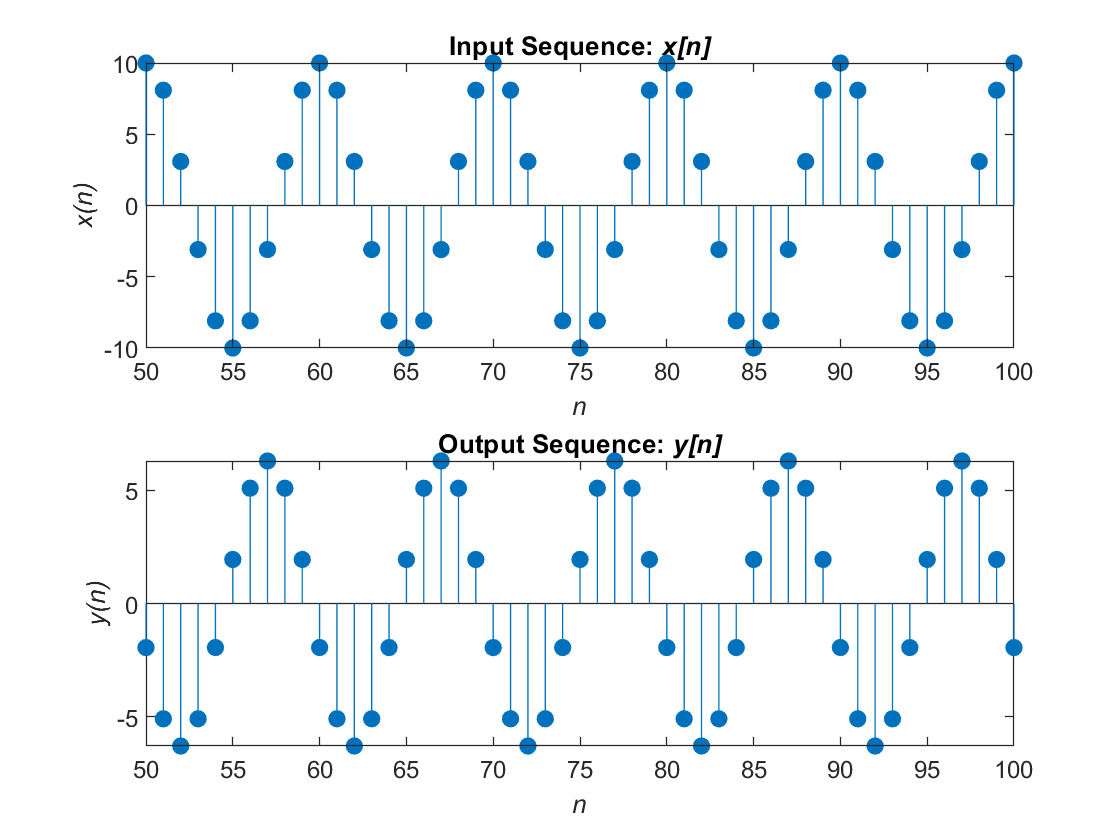

n = 0:150; xn = 10*cos(0.2*pi.*n);
yn = filter(h,1,xn);
figure,
subplot(2,1,1), stem(n(51:101),xn(51:101),'filled') 
title('Input Sequence: \it{x[n]}')
xlabel('\it{n}')
ylabel('\it{x(n)}');
subplot(2,1,2), stem(n(51:101),yn(51:101),'filled')

title('Output Sequence: \it{y[n]}')
xlabel('\it{n}')
ylabel('\it{y(n)}');

**(c)** Can you confirm that $y[n]$ corresponds to samples of the derivative of the signal whose samples are given by $x[n]$?

**Solution:** 

The differentiator is performing t he derivative operator on our input sequency $x[n] = 10\cos(0.2\pi n)$

This corresponds to the first difference operation at each sample of our input $x[n]$. Analyzing the output sequence we can see that the resulting samples are a 90 degree phase shifted and amplitude scaled verison of the input sequence, which corresponds to the differentiator taking the derivative of the input sequence samples. 

So for the output we get $y[n] = -(10)(0.2\pi)\sin(0.2\pi n) \rightarrow -2\pi\sin(0.2\pi n)$, which is what we have in the graph above. 

## Problem 6.5

#### **Text Problem 10.49 (Page 619)** 

Specifications of a bandstop filter are: $\omega_{\mathrm{p}_1}=0.4\mathrm{\pi},$ $A_{\mathrm{p}_1}=0.5$dB, $\omega_{\mathrm{s}_1}=0.55\mathrm{\pi},$ $\omega_{\mathrm{s}_2}=0.65\mathrm{\pi},$ $A_{\mathrm{s}}=55$dB, $\omega_{\mathrm{p}_2}=0.75\mathrm{\pi},$ and $A_{\mathrm{p}_2}=1$dB.

clc; close all; clear;

**(a)** Design a minimum length linear-phase FIR filter using the Kaiser window. Provide a plot similar to Figure 10.17. Do not use the `fir1` function.

**Solution**: 

**MATLAB script**: 

% Design Specifications
Ap1 = 0.5; As = 55; Ap2 = 1; 
wp1 = 0.4*pi; ws1 = 0.55*pi; 
ws2 = 0.65*pi; wp2 = 0.75*pi;
dw1 = ws1-wp1; dw2 = wp2-ws2; 
wc1 = (ws1+wp1)/2; wc2 = (ws2+wp2)/2;
% Calculate the Absolute passband and stopband ripple values
[dp1,ds1] = spec_convert(Ap1,As,'rel','abs');
[dp2,ds2] = spec_convert(Ap2,As,'rel','abs');
d = min(ds1,ds2); A = ceil(-20*log10(d));
% Calculate the order of the FIR filter: M
M = ceil((A-8)/(2.285*dw1))+1; M = 66; L = M+1;

After some iterations, I initally calculated the order of the filter to be $M = 46$. However, this value did not satisfy the design requirements as the higher stopband value of $w_{s2} = 0.65\pi$ was not within the stopband attentuation value of $A_s = -55$dB. Thus, I incremented the value of $M$by 2 because we want it to be a Type-I FIR filter until I reached the value of $M = 66$, which is the minimum value that achieved the design requirements. 

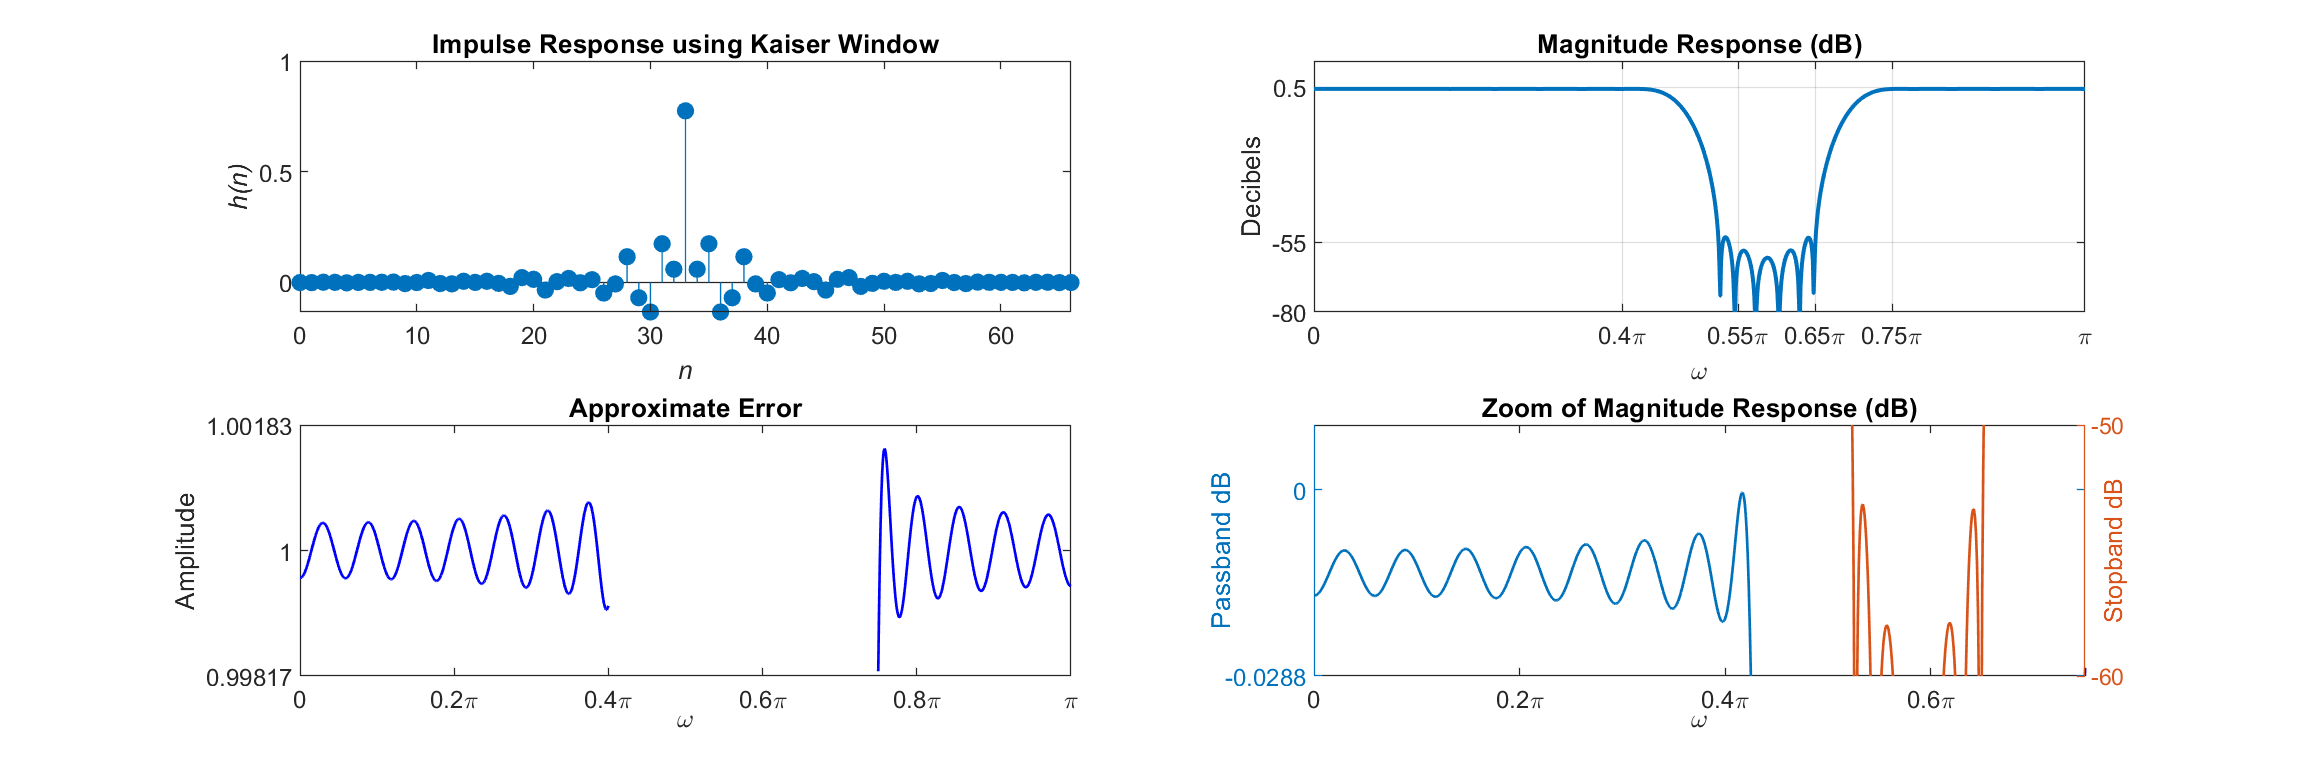

% Obtain the Beta value for A > 50
Beta = 0.1102*(A - 8.7);
% Kaiser Window
w = (kaiser(L,Beta))';
% Calcualte the desired impulse response from the ideal
hd = ideal_lp(wc1,L) + ideal_lp(pi,L) - ideal_lp(wc2,L);
% Multiply Desired Impulse with Kaiser Window
h = hd.*w; n = 0:L-1;
% Frequency Response
N = 1000; om = linspace(0,pi,N+1); Dom = pi/N;
Ip1 = ceil(wp1/Dom); Ip2 = floor(wp2/Dom);
Is1 = floor(ws1/Dom); Is2 = ceil(ws2/Dom);
%Ip1 = ceil((wp+0.05*pi)/Dom); Is1 = ceil(0.4*pi/Dom);
H = freqz(h,1,om); magH = abs(H);
magdb = 20*log10(magH/max(magH)); 
[Hr,om] = zerophase(h,1,om);
% Plot Results
figure('Units','inches','Position',[0,0,12,4]); 
% Impulse Response Plot
subplot(2,2,1), stem(n,h,'filled')
xlabel('\it{n}'), ylabel('\it{h(n)}')
title('Impulse Response using Kaiser Window'), xlim([0 M])
% Magnitude Response Plot in dB
subplot(2,2,2), plot(om/pi,magdb,'LineWidth',1.5), grid on
title('Magnitude Response (dB)'), ylabel('Decibels')
xlabel('\omega'), xticks([0 0.4 0.55 0.65 0.75 1]), ylim([-80 10])
yticks([-80 -55 0.5])
xticklabels({'0','0.4\pi','0.55\pi','0.65\pi','0.75\pi','\pi'}); 
% Approximation Error Plot
subplot(2,2,3); 
plot(om(1:Ip1+1)/pi,Hr(1:Ip1+1),'b',...
    om(Is1+1:Is2+1)/pi,Hr(Is1+1:Is2+1)-1,'b',...
    om(Ip2+1:end)/pi,Hr(Ip2+1:end),'b','linewidth',1); hold on;
plot([0,1],[0,0],'k','linewidth',0.5); axis([0,1,-0.01,0.01]);
title('Approximate Error','fontsize',10); 
ylabel('Amplitude'); ylim([1-d 1+d]), yticks([1-d 1 1+d])
xlabel('\omega','VerticalAlignment','middle');
set(gca,'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
%set(gca,'ytick',[-0.1,0,0.1]); grid on; 
% Zoom of Bandstop
subplot(2,2,4); 
[AX,H1,H2] = plotyy(om(1:Is1+1)/pi,magdb(1:Is1+1),...
    om(Ip1+1:Ip2+1)/pi,magdb(Ip1+1:Ip2+1)); hold on;
set(H1,'linewidth',1); set(H2,'linewidth',1);
plot(om(Is2+1:end)/pi,magdb(Is2+1:end),'b','linewidth',1);
title('Zoom of Magnitude Response (dB)','fontsize',10);
set(get(AX(1),'Ylabel'),'String','Passband dB',...
    'VerticalAlignment','middle');
set(get(AX(2),'Ylabel'),'String','Stopband dB',...
    'VerticalAlignment','bottom');
xlabel('\omega','VerticalAlignment','middle');
set(AX(1),'YLim',[-dp1 0.01]); set(AX(2),'YLim',[-60,-50]);
set(AX(1),'Xtick',[0  .2  .4  .6  .8  1]);
set(AX(1),'Ytick',[-dp1 0]); set(AX(2),'Ytick',[-60 -50]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(AX(2),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 

**(b)** Verify your design using the `fir1` and `kaiserord` functions. Comment on your verification.

**Solution:** 

[M,wn,beta,ftype] = kaiserord([wp1 ws1 ws2 wp2]/pi,[1 0 1], [dp1 d dp2]);
h = fir1(M,wn,ftype,kaiser(M+1,beta)); M, n = 0:M;

M = 66

Here, the kaiserord() function verified my findings of $M = 66$ to be the minimum length to satisfy the design requirements

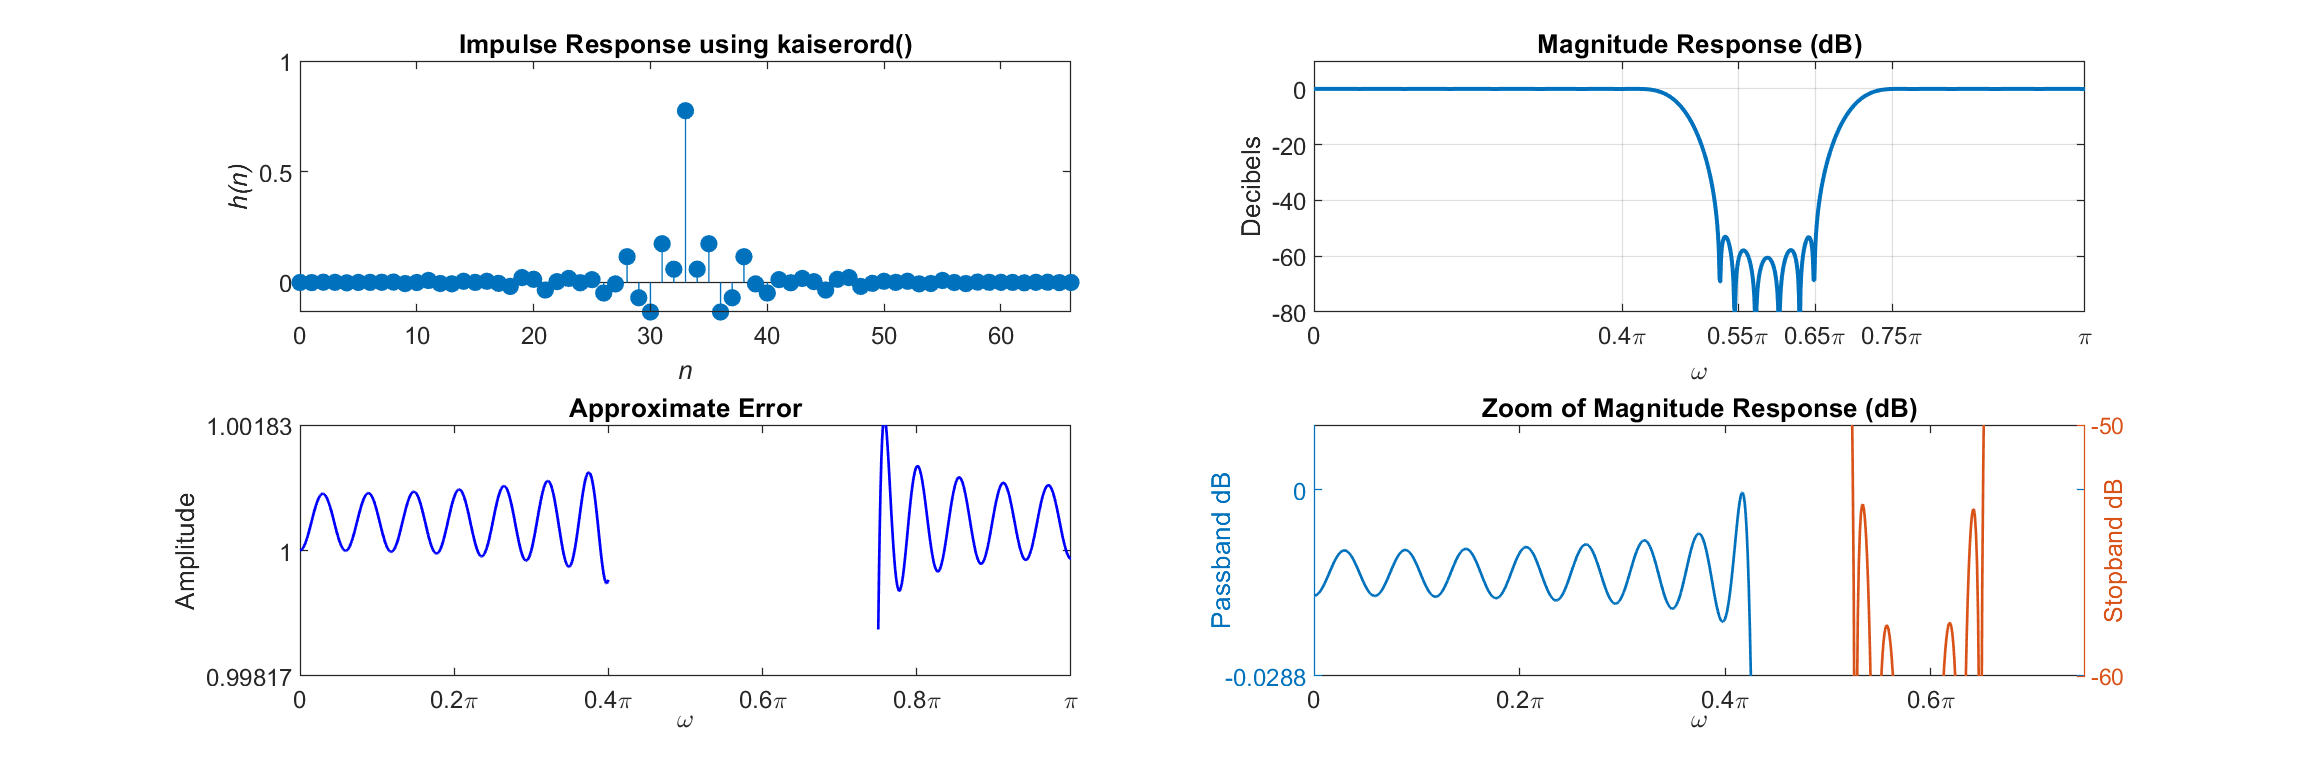

w = linspace(0,1,1001)*pi;
H = freqz(h,1,w);
Hmag = abs(H);
Hdb = 20*log10(Hmag./max(Hmag));
[Hr,om] = zerophase(h,1,w);
figure('Units','inches','Position',[0,0,12,4]); 
subplot(2,2,1), stem(n,h,'filled')
xlabel('\it{n}'), ylabel('\it{h(n)}')
title('Impulse Response using kaiserord()')
xlim([0 M])
subplot(2,2,2), plot(w/pi,Hdb,'LineWidth',1.5), grid on, 
title('Magnitude Response (dB)'), ylabel('Decibels')
xlabel('\omega'), xticks([0 0.4 0.55 0.65 0.75 1])
ylim([-80 10]) 
xticklabels({'0','0.4\pi','0.55\pi','0.65\pi','0.75\pi','\pi'});
% Approximation Error Plot
subplot(2,2,3); 
plot(om(1:Ip1+1)/pi,Hr(1:Ip1+1),'b',...
    om(Is1+1:Is2+1)/pi,Hr(Is1+1:Is2+1)-1,'b',...
    om(Ip2+1:end)/pi,Hr(Ip2+1:end),'b','linewidth',1); hold on;
plot([0,1],[0,0],'k','linewidth',0.5); axis([0,1,-0.01,0.01]);
title('Approximate Error','fontsize',10); 
ylabel('Amplitude'); ylim([1-d 1+d]), yticks([1-d 1 1+d])
xlabel('\omega','VerticalAlignment','middle');
set(gca,'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
%set(gca,'ytick',[-0.1,0,0.1]); grid on; 
% Zoom of Bandstop
subplot(2,2,4); 
[AX,H1,H2] = plotyy(om(1:Is1+1)/pi,magdb(1:Is1+1),...
    om(Ip1+1:Ip2+1)/pi,magdb(Ip1+1:Ip2+1)); hold on;
set(H1,'linewidth',1); set(H2,'linewidth',1);
plot(om(Is1+1:Is2+1)/pi,Hdb(Is1+1:Is2+1),'b','linewidth',1);
title('Zoom of Magnitude Response (dB)','fontsize',10);
set(get(AX(1),'Ylabel'),'String','Passband dB',...
    'VerticalAlignment','middle');
set(get(AX(2),'Ylabel'),'String','Stopband dB',...
    'VerticalAlignment','bottom');
xlabel('\omega','VerticalAlignment','middle');
set(AX(1),'YLim',[-dp1 0.01]); set(AX(2),'YLim',[-60 -50 ]);
set(AX(1),'Xtick',[0  .2  .4  .6  .8  1]);
set(AX(1),'Ytick',[-dp1 0]); set(AX(2),'Ytick',[-60 -50]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(AX(2),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'});

**Comment**: 

After reviewing both approaches, I was able to satisfy the design requirements for a minimum length of $M = 66$ for the FIR filter. 

## Problem 6.6

#### Bandpass filter design: 

Consider the following specifications


$$\begin{array}{rcl}
\text{Lower stopband edge} &:& 0.3\pi, \quad \text{Upper stopband edge} &:& 0.6\pi; \quad  \text{minimum stopband attenuation}&:& 50\mathrm{dB} \\
\text{Lower passband edge} &:& 0.4\pi, \quad \text{Upper passband edge} &:& 0.5\pi; \quad  \text{maximum passband ripple}&:& 0.5\mathrm{dB}
\end{array}$$


**(a)** Design a bandpass filter to satisfy above specifications using the Hamming window techique. Plot the impulse response and the magnitude response in dB of the designed filter using $(2\times1)$ subplots in one figure. Do not use the `fir1` function.

**MATLAB script**: 

clc; close all; clear;
ws1 = 0.3*pi; ws2 = 0.6*pi;
wp1 = 0.4*pi; wp2 = 0.5*pi;
delW =  min(wp1-ws1,ws2-wp2);
L = ceil(6.6*pi/delW)+1; M = L-1

M = 66

n = 0:M; wc1 = (ws1+wp1)/2; wc2 = (wp2+ws2)/2;
hd = ideal_lp(wc2,L) - ideal_lp(wc1,L);
win = hamming(L)'; h = hd.*win;
[db,mag,pha,grd,w] = freqz_m(h,1); delta_w = 2*pi/1000;
Rp = -min(db(wp1/delta_w+1:wp2/delta_w)); % Actual passband ripple

As = -round(max(db(ws2/delta_w+1:1:501))); % Min stopband attenuation
Rp, As

Rp = 0.0488

As = 51

These calculations above show that the stopband attentuation is a value fo 51 dB and the passband ripple is 0.0488, which satisfy the design requirements.

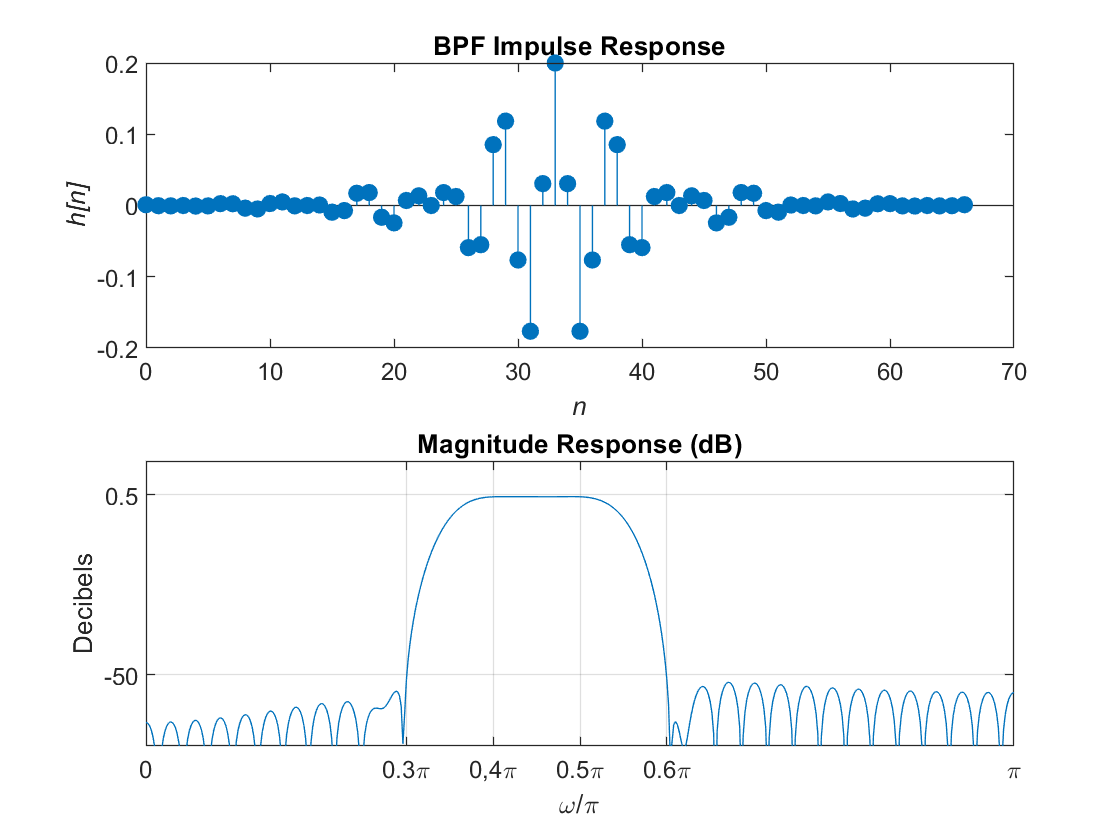

figure;
subplot(2,1,1), stem(n,h,'filled'), title('BPF Impulse Response')
xlabel('\it{n}'), ylabel('\it{h[n]}')
subplot(2,1,2), plot(w/pi,db), title('Magnitude Response (dB)')
xlabel('\omega/\pi'), ylabel('Decibels'), ylim([-70 10])
xticks([0 0.3 0.4 0.5 0.6 1]), yticks([-50 0.5]), grid on
xticklabels({'0','0.3\pi', '0,4\pi','0.5\pi','0.6\pi','\pi'}); 

**(b)** Repeat part (a) using the `fir1` function.

**MATLAB script**: 

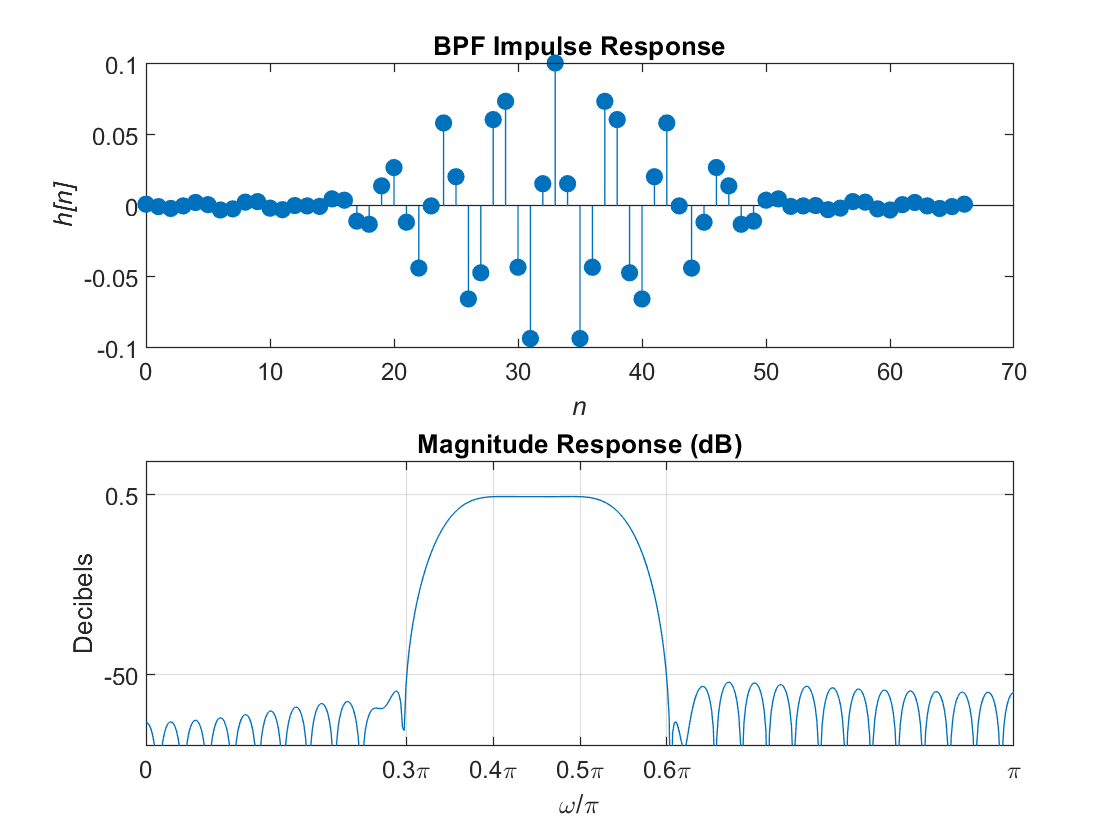

h1 = fir1(M,[0.4 0.5],"bandpass",hamming(L)); 
omega = linspace(0,pi,512); H = freqz(h,1,omega);
figure
subplot(2,1,1), stem(n,h1,'filled'), title('BPF Impulse Response')
xlabel('\it{n}'), ylabel('\it{h[n]}')
subplot(2,1,2), plot(omega/pi,mag2db(abs(H))), title('Magnitude Response (dB)')
xlabel('\omega/\pi'), ylabel('Decibels'), ylim([-70 10])
xticks([0 0.3 0.4 0.5 0.6 1]), yticks([-50 0.5]), grid on
xticklabels({'0','0.3\pi','0.4\pi','0.5\pi','0.6\pi','\pi'}); 

## Problem 6.7

#### **Modified version of the Text Problem 10.22 (Page 615)** 

Consider the type-III linear-phase FIR filter characterized by antisymmetric impulse response and even $M$:


$$h[n] = -h[M-n], \quad 0\leq n\leq M; \qquad M\sim\text{\ even} \qquad\qquad$$


**(a)** Show that the amplitude response $A(\mathrm{e}^{\j\omega})$ is given by $(10.34)$ with coefficients $c[k]$ given in $(10.35)$, that is


$$A(\mathrm{e}^{\j\omega}) = \sum_{k=1}^{M/2} c[k] \sin(\omega k) \qquad\qquad(6.7a.1)$$


with coefficients $c[k]$ given by


$$c[k] = 2h\left[\frac{M}2-k\right],\quad 
 k = 1,2 \ldots, \frac{M}2. \qquad\qquad(6.7a.2)$$


**Solution**: 

First we substitute the impulse into the DTFT equation and also knowing that $M$is even, we have:


$$H(e^{j\omega}) = \sum_{k=0}^{M} h[k]e^{-j\omega k}$$



$$\qquad = e^{-j\omega M/2} \sum_{k=0}^{M} h[k]e^{-j\omega(M/2 +k)}$$



$$\qquad = e^{-j\omega M/2} \sum_{k=0}^{M/2} h[k]e^{-j\omega(M/2 +k)} + e^{-j\omega M/2} \sum_{k=M/2 + 1}^{M} h[k-M/2]e^{-j\omega(M/2 +k)}$$


Because this is antisymmetric even, $h[M/2] = -h[M/2]$, which means $h[M/2] = 0$


$$\qquad = e^{-j\omega M/2} \sum_{k=1}^{M/2} h[k]e^{-j\omega(M/2 +k)} + e^{-j\omega M/2} \sum_{k=M/2 + 1}^{M} h[k-M/2]e^{-j\omega(M/2 +k)}$$


using the identity $j2\sin(\theta) = e^{j\theta} - e^{-j\theta}$


$$H(e^{j\omega}) = je^{-j\omega M/2} \sum_{k=0}^{M/2}2h(M/2 -k)\sin(\omega M/2-k)$$


Thus, substituting $k = M/2 - k$ and $j = e^{j\frac{\pi}{2}$ into the above equation and $c[k] = 2h[M/2-k]$


$$H(e^{j\omega}) = \sum_{k=1}^{M/2}c[k]\sin(\omega k)e^{-j\left(\frac{\pi}{2} - \omega M/2\right)$$


Thus, the $A(e^{j\omega})$ can be represented by the term 


$$\left(\sum_{k=1}^{M/2}c[k]\sin\omega k\right)$$


**(b)** Show that the amplitude response $A(\mathrm{e}^{\j\omega})$ can be further expressed as in $(10.36)$, that is


$$A(\mathrm{e}^{\j\omega}) = \sin(\omega) \sum_{k=0}^{M/2-1} \tilde{c}[k] \cos(\omega k) \qquad\qquad(6.7b.1)$$


with coefficients $\tilde{c}[k]$ given by the recursive algorithm (recursing backwards)


$$\begin{array}{rcl}
\tilde{c}\left[\frac{M}2-1\right] &=& 2c\left[\frac{M}2\right] \\
\tilde{c}\left[\frac{M}2-2\right] &=& 2c\left[\frac{M}2-1\right] \\
\tilde{c}[k] &=& 2c[k+1] +\tilde{c}[k+2], \quad k = \frac{M}2-3:-1:1 \\
\tilde{c}[0] &=&c[1]+\frac12\tilde{c}[2]
\end{array} \qquad\qquad(6.7b.2)$$


**Hint**: To convert $(6.7a.1)$ into $(6.7b.1)$, we start with $(6.7b.1)$ and use the following trigonometric identity


$$\cos(A)\sin(B) = \textstyle\frac12\bigl[\sin(A+B)-\sin(A-B)\bigr] .\qquad\qquad(6.7b.3)$$


Next, simplify to obtain a trigonometric polynomial in $\sin(k\omega)$ and then identifiy the coefficients with those in $(6.7b.1) to prove $(6.7b.3).$

**Solution**: 

**(c)** Let $h[n] = \{\underset{\uparrow}{1},2,3,4,0,-4,-3,-2,-1\}$ be the impulse response of a type-III linear-phase FIR filter. Determine the coefficient arrays $\{c[k]\}_{k=1}^4$ and $\{\tilde{c}[k]\}_{k=0}^3$, using results from parts (a) and (b), respectively. Determine the respective amplitude response functions and verify your results.

**Solution**: 

clc; close all; clear;
M = 8;
n = 0:8;
h = [1 2 3 4 0 -4 -3 -2 -1];
k = 1:M/2; l = M/2-k+1;
c = 2.*h(l)

c =      8     6     4     2


Thus, the coeffients for $\{c[k]\}_{k=1}^4$ would be $\{8,6,4,2\}$

**Verification**: 

## Problem 6.8

#### **Text Problem 10.37 (Page 617)** 

A lowpass FIR filter is to be designed using the specifications: $\omega_\mathrm{p}=0.3\pi,$ $A_\mathrm{p}=0.5\ \mathrm{dB},$ $\omega_\mathrm{s}=0.5\pi,$ and $A_\mathrm{s}=50\ \mathrm{dB}.$

**(a)** Use the Parks-McClellan algorithm to obtain a minimum length linear-phase filter impulse response. Indicate the length of your designed filter.

**MATLAB script**: 

clc; close all; clear;
fp = 0.3; fs = 0.5; df = fs-fp; fc = (fp+fs)/2; Ap = 0.5; As = 50;
[dp,ds] = spec_convert(Ap,As,'rel','abs');
% Estimate the filter order using FIRPMORD function
[M,fo,ao,W] = firpmord([fp,fs],[1,0],[dp,ds]); M

M = 18

Using the Parks-McClellan algorithm, I've calculated that the minimum length to achieve these design specifications for the lowpass FIR filter is length $M = 18$, initially. 

However, after noticing this value did not satisfy the design specifications, I increased the value of $M$twice until I reached a value of $M = 20$ to meet the design requirements. 

**(b)** Provide a plot figure similar to Figure 10.12 in the text with appropriate labels and tick marks.

**MATLAB script**: 

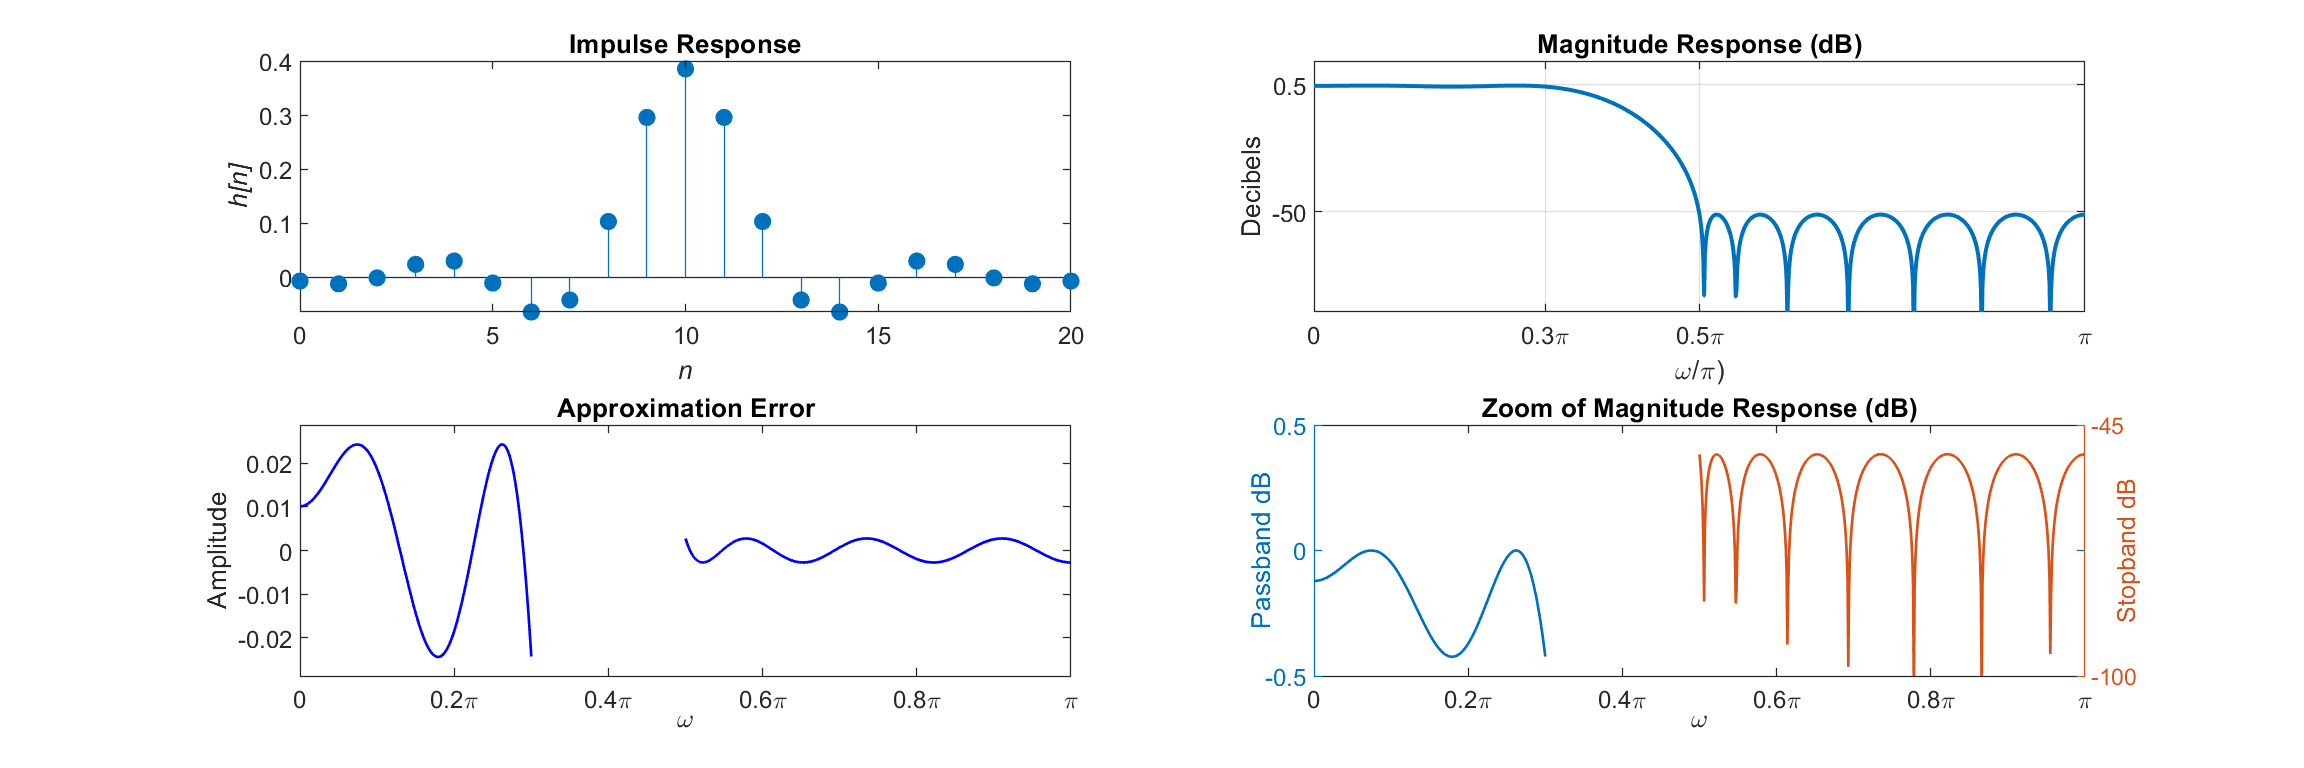

M = 20;
[h,delta] = firpm(M,fo,ao,W);
n = 0:M; omega = linspace(0,pi,1001);
H = freqz(h,1,omega);
% Frequency Response
N = 1000; om = linspace(0,pi,N+1); Dom = 1/N;
Ip = ceil(fp/Dom);
Is = floor(fs/Dom);
%Ip1 = ceil((wp+0.05*pi)/Dom); Is1 = ceil(0.4*pi/Dom);
magH = abs(H);
magdb = 20*log10(magH/max(magH)); 
[Hr,om] = zerophase(h,1,om);
% Plot Results
figure('Units','inches','Position',[0,0,12,4]);
% Plot Impulse Response
subplot(2,2,1), stem(n,h,'filled'), title('Impulse Response') 
xlabel('\it{n}'), ylabel('\it{h[n]}'), xlim([0 M])
% Plot Magnitude Response
subplot(2,2,2), plot(omega/pi, mag2db(abs(H)),'LineWidth',1.5)
title('Magnitude Response (dB)')
xlabel('\omega/\pi)'), ylabel('Decibels'), ylim([-90 10])
xticks([0 0.3 0.5 1]), yticks([-50 0.5]), grid on
xticklabels({'0','0.3\pi','0.5\pi','\pi'}); 
% Approximation Error Plot
subplot(2,2,3); 
plot(om(1:Ip+1)/pi,Hr(1:Ip+1)-1,'b',om(Is+1:end)/pi,Hr(Is+1:end),'b','linewidth',1); 
axis([0,1,-0.0035,0.0035]); 
title('Approximation Error','fontsize',10);
ylabel('Amplitude'), ylim([-dp dp])
xlabel('\omega','VerticalAlignment','middle');
set(gca,'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
% Zoom of Log-Magnitude Plot
subplot(2,2,4); 
[AX,H1,H2] = plotyy(om(1:Ip+1)/pi,magdb(1:Ip+1),...
    om(Is+1:end)/pi,magdb(Is+1:end)); 
set(H1,'linewidth',1); set(H2,'linewidth',1);
title('Zoom of Magnitude Response (dB)','fontsize',10);
xlabel('\omega','VerticalAlignment','middle');
set(get(AX(1),'Ylabel'),'String','Passband dB',...
    'VerticalAlignment','middle');
set(get(AX(2),'Ylabel'),'String','Stopband dB',...
    'VerticalAlignment','bottom');
set(AX(1),'YLim',[-1/2 1/2]); set(AX(2),'YLim',[-100,-45]);
set(AX(2),'Ytick',[-100,-45]);
set(AX(1),'Xtick',[0  .2  .4  .6  .8  1]); set(AX(1),'Ytick',[-.5 0 .5]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(AX(2),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 

## Problem 6.9

#### **Text Problem 10.58 (Page 621)** 

Specifications of bandstop digital filter are given below:


$$\begin{array}{rcl}
|H(\mathrm{e}^{\j\omega})| &=& 1\pm0.01, \qquad &0.00\pi\leq |\omega| \leq  0.35\pi \\
|H(\mathrm{e}^{\j\omega})| &=& 0\pm0.004, \qquad &0.45\pi\leq |\omega| \leq  0.55\pi \\
|H(\mathrm{e}^{\j\omega})| &=& 1\pm0.01, \qquad &0.65\pi\leq |\omega| \leq  \pi 
\end{array}$$


**(a)** Design an FIR filter using the Parks-McClellan algorithm to obtain a minimum length linear-phase filter impulse response. Indicate the length of your designed filter.

**MATLAB script**: 

clc; close all; clear;
wp1 = 0.35*pi; ws1 = 0.45*pi;
wp2 = 0.65*pi; ws2 = 0.55*pi;
dp1 = 0.01; ds = 0.004; dp2 = 0.01;
% Estimate Filter using FIRPMORD function
f = [wp1,ws1,ws2,wp2]/pi; % Band-edge array
a = [1 0 1]; % Band-edge desired gain
dev = [dp1,ds,dp2]; % Band tolerance
[M,fo,ao,W] = firpmord(f,a,dev); M

M = 44

Using the Parks-McClellan algorithm, I've calculate the minimum length for the linear-phase impulse response to be 


$$M = 44$$


**(b)** Provide a plot figure similar to Figure 10.32 in the text with appropriate labels and tick marks.

**MATLAB script**: 

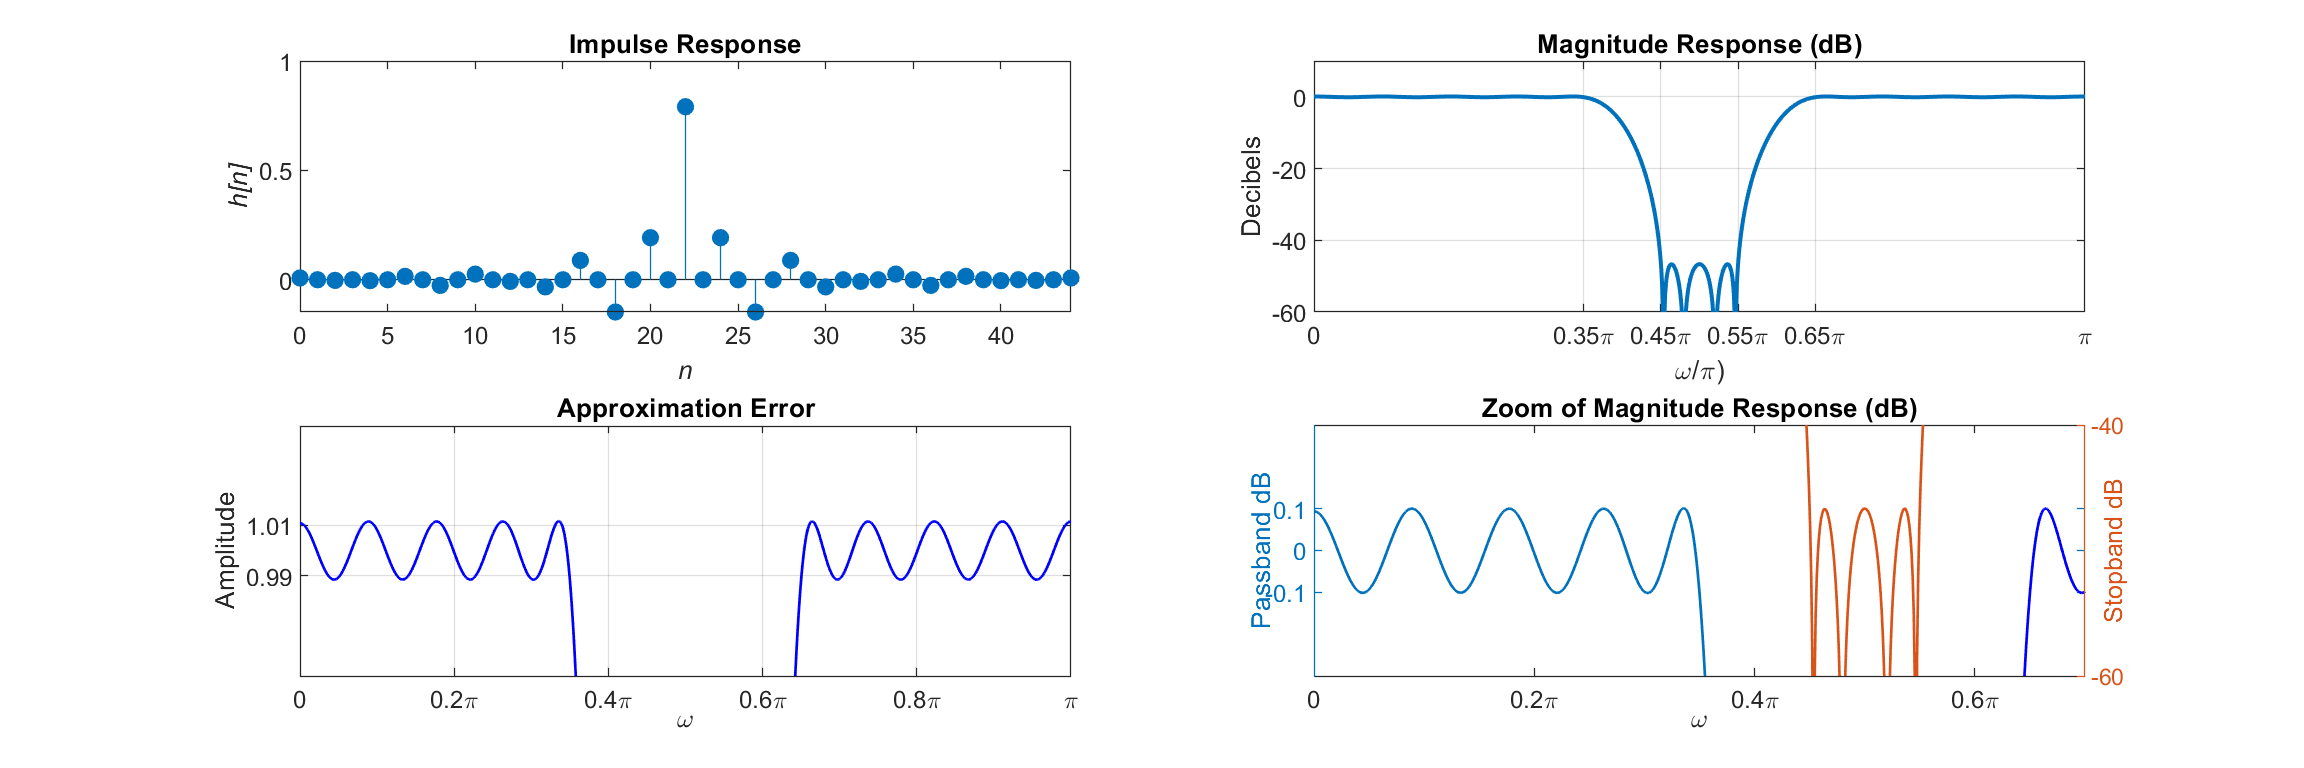

% Filter Design using FIRPM function
[h,delta] = firpm(M,fo,ao,W);
n = 0:M; om = linspace(0,pi,1000);
H = freqz(h,1,om);
magdb = mag2db(abs(H));
% Frequency Response
Dom = pi/1000;
Ip1 = ceil(wp1/Dom); Ip2 = floor(wp2/Dom);
Is1 = floor(ws1/Dom); Is2 = ceil(ws2/Dom);
[Hr,om] = zerophase(h,1,om);
% Plot Results
figure('Units','inches','Position',[0,0,12,4]);
% Plot Impulse Response
subplot(2,2,1), stem(n,h,'filled'), title('Impulse Response') 
xlabel('\it{n}'), ylabel('\it{h[n]}'), xlim([0 M])
% Plot Magnitude Response in dB
subplot(2,2,2), plot(om/pi, mag2db(abs(H)),'LineWidth',1.5)
title('Magnitude Response (dB)')
xlabel('\omega/\pi)'), ylabel('Decibels'), ylim([-60 10])
xticks([0 0.35 0.45 0.55 0.65 1])
xticklabels({'0','0.35\pi','0.45\pi','0.55\pi','0.65\pi','\pi'})
grid on
% Approximation Error Plot
subplot(2,2,3); 
plot(om(1:Is1+1)/pi,Hr(1:Is1+1),'b',...
    om(Ip1+1:Ip2+1)/pi,Hr(Ip1+1:Ip2+1)-1,'b',...
    om(Is2+1:end)/pi,Hr(Is2+1:end),'b','linewidth',1); hold on;
plot([0,1],[0,0],'k','linewidth',0.5); axis([0,1,-0.01,0.01]);
title('Approximation Error','fontsize',10);  
ylabel('Amplitude'); ylim([0.95 1.05])
xlabel('\omega','VerticalAlignment','middle');
set(gca,'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(gca,'ytick',[0.99,1.01]); grid on; 
% Zoom of Bandstop
subplot(2,2,4); 
[AX,H1,H2] = plotyy(om(1:Is1+1)/pi,magdb(1:Is1+1),...
    om(Ip1+1:Ip2+1)/pi,magdb(Ip1+1:Ip2+1)); hold on;
set(H1,'linewidth',1); set(H2,'linewidth',1);
plot(om(Is2+1:end)/pi,magdb(Is2+1:end),'b','linewidth',1);
title('Zoom of Magnitude Response (dB)','fontsize',10);
set(get(AX(1),'Ylabel'),'String','Passband dB',...
    'VerticalAlignment','middle');
set(get(AX(2),'Ylabel'),'String','Stopband dB',...
    'VerticalAlignment','bottom');
xlabel('\omega','VerticalAlignment','middle');
set(AX(1),'YLim',[-0.3 0.3]); set(AX(2),'YLim',[-60,-40]);
set(AX(1),'Xtick',[0  .2  .4  .6  .8  1]);
set(AX(1),'Ytick',[-.1 0 .1]); set(AX(2),'Ytick',[-60 -40]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 
set(AX(2),'Xtick',[0  .2  .4  .6  .8  1]);
xticklabels({'0','0.2\pi','0.4\pi','0.6\pi','0.8\pi','\pi'}); 

## Problem 6.10

Specifications of an FIR filter are given below:

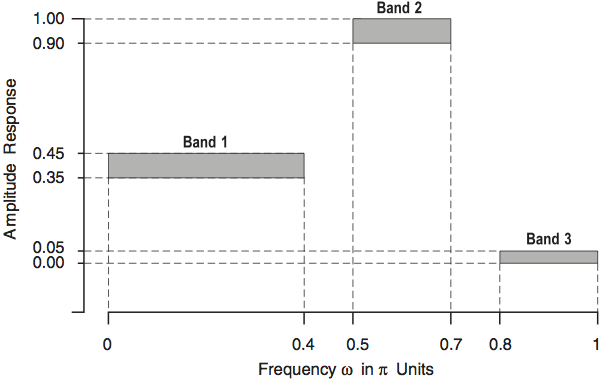

**(a)** Design a lowest-order equiripple linear-phase FIR filter to satisfy the above specifications. Indicate your resulting filter order.

**Solution:** 

clc; close all; clear;
w1 = 0; w2 = 0.4*pi; d1 = 0.05; % Band 1 
w3 = 0.5*pi; w4 = 0.7*pi; d2 = 0.05; % Band 2
w5 = 0.8*pi; w6 = pi; d3 = 0.025; % Band 3
weights = [d3/d1, d3/d2, 1]; % weights for PM function
dw = min((w3-w2),(w5-w3)); % min width between bands
M = ceil((-20*log10((d1*d2*d3)^(1/3))-8)/(2.285*dw))

M = 28

Here, I've calculated that the lowest-order value for this filter is $M = 28$.

n = 0:M;
f = [0 w2 w3 w4 w5 pi]/pi;
m = [0.4 0.4 0.95 0.95 0.025 0.025];
h = firpm(M,f,m,weights);

**(b)** Provide a plot of the amplitude response and a plot of the impulse response in one figure using two rows and one column. Comment on your design responses.

**MATLAB script**: 

w = linspace(0,pi,1001);
[Ha w2 P2 L2] = amplresp(h,w);

*** Type-1 Linear-Phase Filter ***


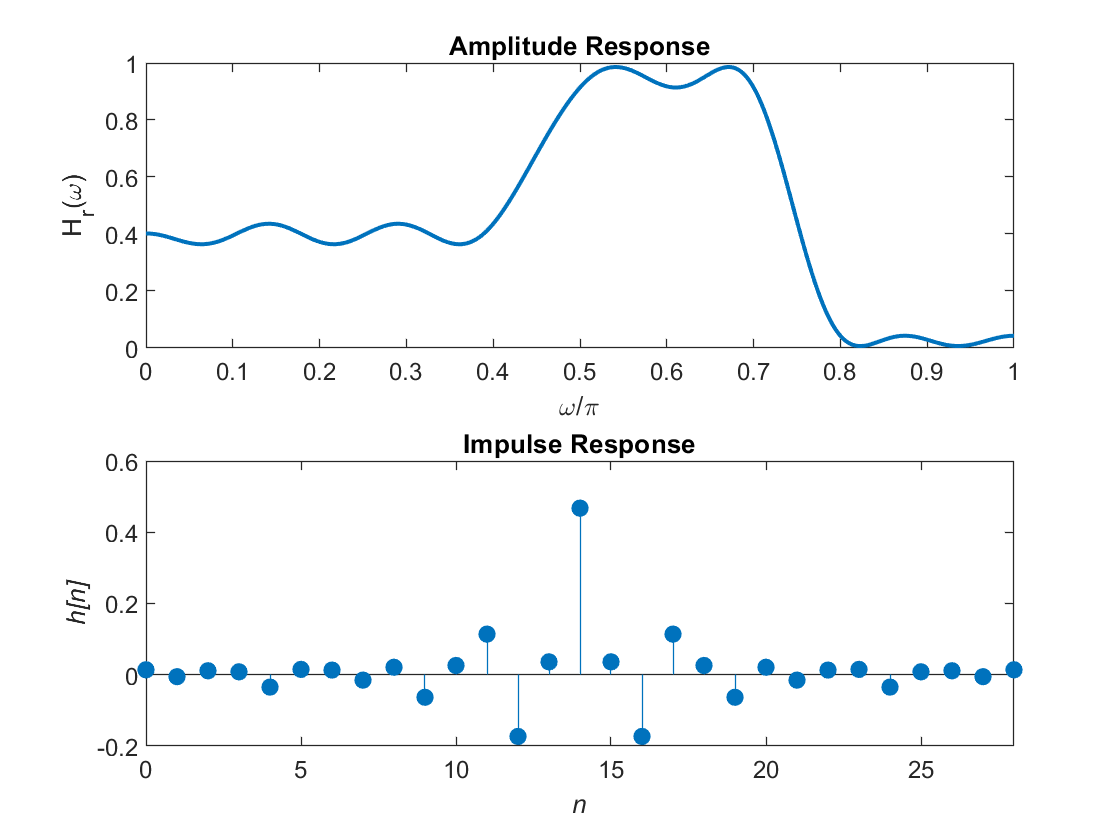

figure
subplot(2,1,1), plot(w/pi,Ha,'LineWidth',1.5), xlabel('\omega/\pi'), ylabel('H_r(\omega)'), title('Amplitude Response')
subplot(2,1,2), stem(n,h,'filled'), xlabel('\it{n}'), xlim([0 M]) 
ylabel('\it{h[n]}'), title('Impulse Response')

**Comment:** 

Observing the plots above, we can see that the Amplitude response falls between the desired gain values at the specified frequencies. Providing further inspection of the minimum and maximum values in each band, we find that:

Band1max = max(Ha(1:401)), Band1min = min(Ha(1:401))

Band1max = 0.4359

Band1min = 0.3641

Band2max = max(Ha(501:701)), Band2min = min(Ha(501:701))

Band2max = 0.9859

Band2min = 0.9140

Band3max = max(Ha(801:1001)), Band3min = min(Ha(801:1001))

Band3max = 0.0429

Band3min = 0.0069

Thus, the amplitude responses are 

$0.3641 \leq A(e^{j\omega}) \leq 0.4359$ in Band 1

$0.9140 \leq A(e^{j\omega}) \leq 0.9859$ in Band 2

$0.0069 \leq A(e^{j\omega}) \leq 0.0429$ in Band 3

which all fall within the desired gain values for the amplitude response, thus the design specifications are satisfied. 

The `spec_convert` function

function [A,B] = spec_convert(C,D,typein,typeout)
%  typein: 'abs' or 'rel' or 'ana'
% typeout: 'abs' or 'rel' or 'ana'
%     C,D: input specifications
%     A,B: output specifications

% Enter your function code below
if nargin > 4
    error('too many input arguments')
end

switch typein
    case 'abs'
        switch typeout
            case 'rel'
                Ap = 20*log10((1+C)/(1-C)); % Relative Output: Passband ripple
                As = floor(20*log10((1+C)/D)); % Relative Output: Stopband Attenuation
                A = Ap; B = As;
            case 'ana'
                Ap = 20*log10((1+C)/(1-C)); % Relative Output: Passband ripple
                As = floor(20*log10((1+C)/D)); % Relative Output: Stopband Attenuation
                A = sqrt(10^(Ap/10)-1); % Analog Output: Passband
                B = floor(10^(As/20)); % Analog Output: Stopband                
        end
    case 'rel'
        switch typeout
            case 'abs'
                dp = (10^(C/20)-1)/(1+10^(C/20)); % Absolute Output: Passband Error
                ds = (1+dp)/(10^(D/20)); % Absolute Output: Stopband Error
                A = dp; B = ds;
            case 'ana'
                epsilon = sqrt(10^(C/10)-1); % Analog Output: Passband
                B = floor(10^(D/20)); % Analog Output: Stopband
                A = epsilon;
        end
   case 'ana'
        switch typeout
            case 'rel'
                Ap = round(10*log10(C^(2)+1),2); % Relative Output: Passband ripple (in dB)
                As = 20*log10(D); % Relative Output: Stopband Attenuation (in dB)
                A = Ap; B = As;
            case 'abs'
                Ap = round(10*log10(C^(2)+1),2); % Relative Output: Passband ripple (in dB)
                As = 20*log10(D); % Relative Output: Stopband Attenuation (in dB)
                dp = (10^(Ap/20)-1)/(1+10^(Ap/20)); % Absolute Output: Passband Error
                ds = (1+dp)/(10^(Ap/20)); % Absolute Output: Stopband Error
                A = dp; B = ds;
        end     
end
end